clearvars
close all
clc

***SECONDARY PORE NETWORK DESIGN OPTIMIZATION ANALYTICAL DIFFUSION MODEL FOR LITHIUM ION BATTERY***

# Data Disclaimer

The National Renewable Energy Laboratory (NREL) is operated for the U.S. Department of Energy (DOE) by Alliance for Sustainable Energy, LLC ("Alliance").

Access to or use of any data or software made available on this server ("Data") shall impose the following obligations on the user, and use of the Data constitutes user's agreement to these terms. The user is granted the right, without any fee or cost, to use or copy the Data, provided that this entire notice appears in all copies of the Data. Further, the user agrees to credit DOE/NREL/ALLIANCE in any publication that results from the use of the Data. The names DOE/NREL/ALLIANCE, however, may not be used in any advertising or publicity to endorse or promote any products or commercial entities unless specific written permission is obtained from DOE/NREL/ ALLIANCE. The user also understands that DOE/NREL/ALLIANCE are not obligated to provide the user with any support, consulting, training or assistance of any kind with regard to the use of the Data or to provide the user with any updates, revisions or new versions thereof. DOE, NREL, and ALLIANCE do not guarantee or endorse any results generated by use of the Data, and user is entirely responsible for the results and any reliance on the results or the Data in general.

USER AGREES TO INDEMNIFY DOE/NREL/ALLIANCE AND ITS SUBSIDIARIES, AFFILIATES, OFFICERS, AGENTS, AND EMPLOYEES AGAINST ANY CLAIM OR DEMAND, INCLUDING REASONABLE ATTORNEYS' FEES, RELATED TO USER'S USE OF THE DATA. THE DATA ARE PROVIDED BY DOE/NREL/ALLIANCE "AS IS," AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING BUT NOT LIMITED TO THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. DOE/NREL/ALLIANCE ASSUME NO LEGAL LIABILITY OR RESPONSIBILITY FOR THE ACCURACY, COMPLETENESS, OR USEFULNESS OF THE DATA, OR REPRESENT THAT ITS USE WOULD NOT INFRINGE PRIVATELY OWNED RIGHTS. IN NO EVENT SHALL DOE/NREL/ALLIANCE BE LIABLE FOR ANY SPECIAL, INDIRECT OR CONSEQUENTIAL DAMAGES OR ANY DAMAGES WHATSOEVER, INCLUDING BUT NOT LIMITED TO CLAIMS ASSOCIATED WITH THE LOSS OF DATA OR PROFITS, THAT MAY RESULT FROM AN ACTION IN CONTRACT, NEGLIGENCE OR OTHER TORTIOUS CLAIM THAT ARISES OUT OF OR IN CONNECTION WITH THE ACCESS, USE OR PERFORMANCE OF THE DATA.

# Authors

This model has been published along with the article below. Please quote it if distributing the model and/or results obtained with it.

**F. L. E. Usseglio-Viretta*, W. Mai*, A. Colclasure*, E. Yi**, M. Doeff**, and K. Smith*, *****Enabling Fast Charging of Lithium Ion Battery Through Secondary/dual Pore Network: Part I – analytical diffusion model*****, Electrochemica Acta, 2019.**

* Transportation and Hydrogen Systems Center, [National Renewable Energy Laboratory](https://www.nrel.gov/transportation/energy-storage.html), Golden, Colorado 80401, USA

** Energy Storage & Distributed Resources Division, Lawrence Berkeley National Laboratory, Berkeley, CA 94720, USA

DOI: [https://doi.org/10.1016/j.electacta.2020.136034](https://doi.org/10.1016/j.electacta.2020.136034)

If you have questions or comments, please send message to: Francois.UsseglioViretta@nrel.gov

Note, that the term 'reference electrode' corresponds to the term 'baseline electrode' in the article. The default values correspond to case #2 of the article.

# How to use

The model uses the MATLAB live editor environment which combines in a unique document texts, figures, equations, code and results. If you wish to see or hide the code, please click on the dedicated buttons in the right as shown in the figure below. In the next sections, you can set parameters using graphic user interface objects such as sliders. Once done, you can either run the model by clickling on the "Run model" button, and then on the "Plot figures" button located in their respective sections. Otherwise, you can run the model clicking on the green arrow 'run' button located in the 'Live editor' tab of the MATLAB ribbon interface. For presentation, you can use the full screen view option, located in the 'View' tab of the MATLAB ribbon interface.

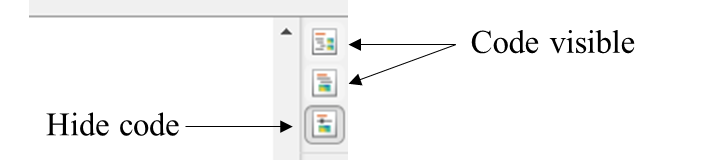

If you are a end-user, please click on the 'hide code' button. If you want to check the code, please click on one of the two other buttons.

# Background

    Fast ion transport along the electrode thickness is required for Lithium ion battery (LIB) to sustain continuous high-rate discharge or charge currents, which is a desired feature for the fast charging of electric vehicle batteries. LIB electrodes have complex porous microstructures, which are linked to the macroscopic performance of these devices. Especially the effective, or macroscopic, ionic diffusion coefficient $D_{\textrm{eff}}$ is related with the porosity $\varepsilon$ and the tortuosity factor $\tau$ (cf. eq. 1). The latter denotes the effect of the convoluted, tortuous, path of the pores that hinders the Li-ion diffusion and is often correlated with the porosity according to the generalized Archie’s relationship (cf. eq. 2) which is an empirical generalization of the Bruggeman analytical law. Previous work has demonstrated tortuosity factor is a key parameter to enable fast charge for thick electrodes without capacity loss induced by degradation (lithium plating in the anode) and/or electrode active material partial utilization due to local electrolyte depletion [1]. It is then relevant for automotive application to design LIB electrodes with the lower through-plane (i.e. along the electrode thickness) tortuosity factor possible, i.e., the higher through-plane effective ionic diffusion coefficient possible.

$\left(1\right)\;\;\;D_n =\frac{D_{\textrm{eff}} }{D_0 }=\frac{\varepsilon }{\tau }$ *with *$D_n$* the normalized diffusion coefficient, and *$D_0$* the bulk (i.e., dense) diffusion coefficient. *$D_{\textrm{eff}}$* and *$D_0$* are expressed in *$m^2 \ldotp s^{-1}$* while *$D_n$*, *$\varepsilon$* and *$\tau$* are adimensional.*

$\left(2\right)\;\;\;\tau =\gamma \varepsilon^{1-\alpha }$ *with *$\gamma$* and *$\alpha \;$*adimensional coefficients specific for each different electrode microstructure. *

    Advance in LIB electrode manufacturing allows to control, to a certain extent, the electrode microstructure architecture. For instance, several groups [2-13] have experimentally tested architectures tailored specifically to increase the through plane ionic diffusion in regards for fast charge application by adding channels or groove-like large pores oriented along the electrode thickness. These voids do not replace the existing pores of the electrode microstructure but consist in a second, coarser, pore network, called **the secondary pore network (SPN)**. The simple idea behind this concept is that lithium ion will first preferentially diffuse through these straight large channels (i.e. through the path of least resistance), and then through the fine pore network to reach the reaction site. Improving the through-plane diffusion allow a more uniform utilization of the electrode along its full thickness. An example of such structured electrode is visible is the figure below.

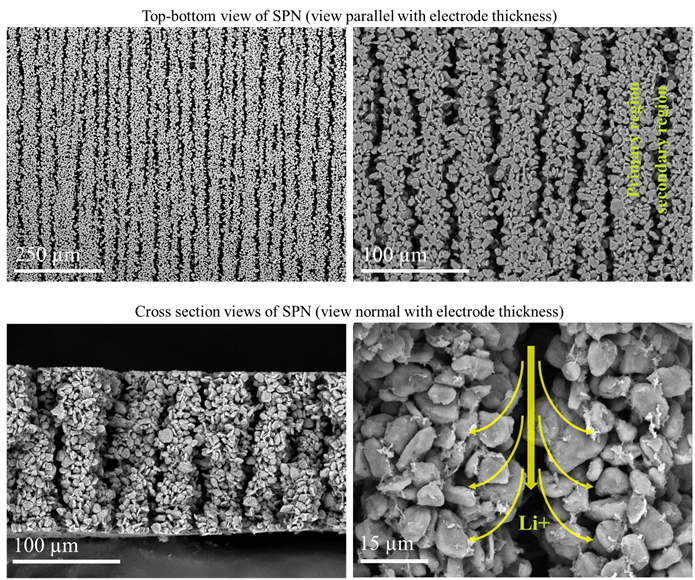

Scanning Electrons Microscope (SEM) images at different magnifications of a graphite anode manufactured with freeze tape casting at Lawrence Berkeley National Laboratory. Electrode is ~150 µm thick with a porosity of 58% and a theoretical areal capacity of 4.5 mAh.cm-2. Primary (channel spacing) and secondary region (channel width) are, respectively, 28±7 µm and 8±3 µm wide.

[1] A. M. Colclasure, A. R. Dunlop, S. E. Trask, B. J. Polzin, A. N. Jansen, and K. Smith, J. Electrochem. Soc., 166(8), A1412 (2019).

[2] J. S. Sander, R. M. Erb, L. Li, A. Gurijala, and Y.-M. Chiang, Nature Energy,1, 16099 (2016).

[3] C.‐J. Bae, C. K. Erdonmez, J. W. Halloran, and Y.‐M. Chiang, Adv.Mater., 25, 1254 (2013).

[4] J.-H. Rakebrandt, P. Smyrek, Y. Zheng, H.J. Seifert, and W. Pfleging, Proc. of SPIE Vol. 10092, 100920M (2017).

[5] J. Park, S. Hyeon, S. Jeonga, and H.-J. Kim, Journal of Industrial and Engineering Chemistry, 70, 178 (2019).

[6] J. B. Habedank, L. Kraft,A. Rheinfeld, C. Krezdorn, A. Jossen, and M. F. Zaeh, J. Electrochem. Soc., 165, 7, A1563 (2018).

[7] S. Behr, R. Amin, Y.-M. Chiang, and A. P. Tomsia, CFI Ceramic Forum International, 92, 4, E39 (2015).

[8] B. Delattre, R. Amin, J. Sander, J. D. Coninck, A. P. Tomsia, and Y.-M. Chiang, J. Electrochem. Soc., 165, 2, A388 (2018).

[9] C. Huang and P. S. Grant, J. Mater. Chem. A, 6, 14689 (2018).

[10] R. Amin, B. Delattre, A. P. Tomsia, and Y.-M. Chianh, ACS Applied Energy Materials, 1, 9, 4976 (2018).

[11] S. W. Sofie, J. Am. Ceram. Soc., 90, 7, 2024 (2007).

[12] M. A. Ghadkolai, S. Creager, J. Nanda, R. K. Bordia, J. Electrochem. Soc.,164, 12, A2603 (2017).

[13] Y. Hwa, E. Yi, H. Shen, Y. Sung, J. Kou, K. Chen, D. Y. Parkinson, M. M. Doeff, E. J. Cairns, Nano Lett. 19, 4731 (2019).

# Analytical model

    The model proposed to **quantify the impact of SPN on ionic diffusion through a simple analytical approach** presented more in details in the associated article. The goal is to find optimal SPN design parameter according to different optimization objectives, aimed to **balance the improved through-plane diffusion and the degraded in-plane diffusion**. The geometry considered is represented below.

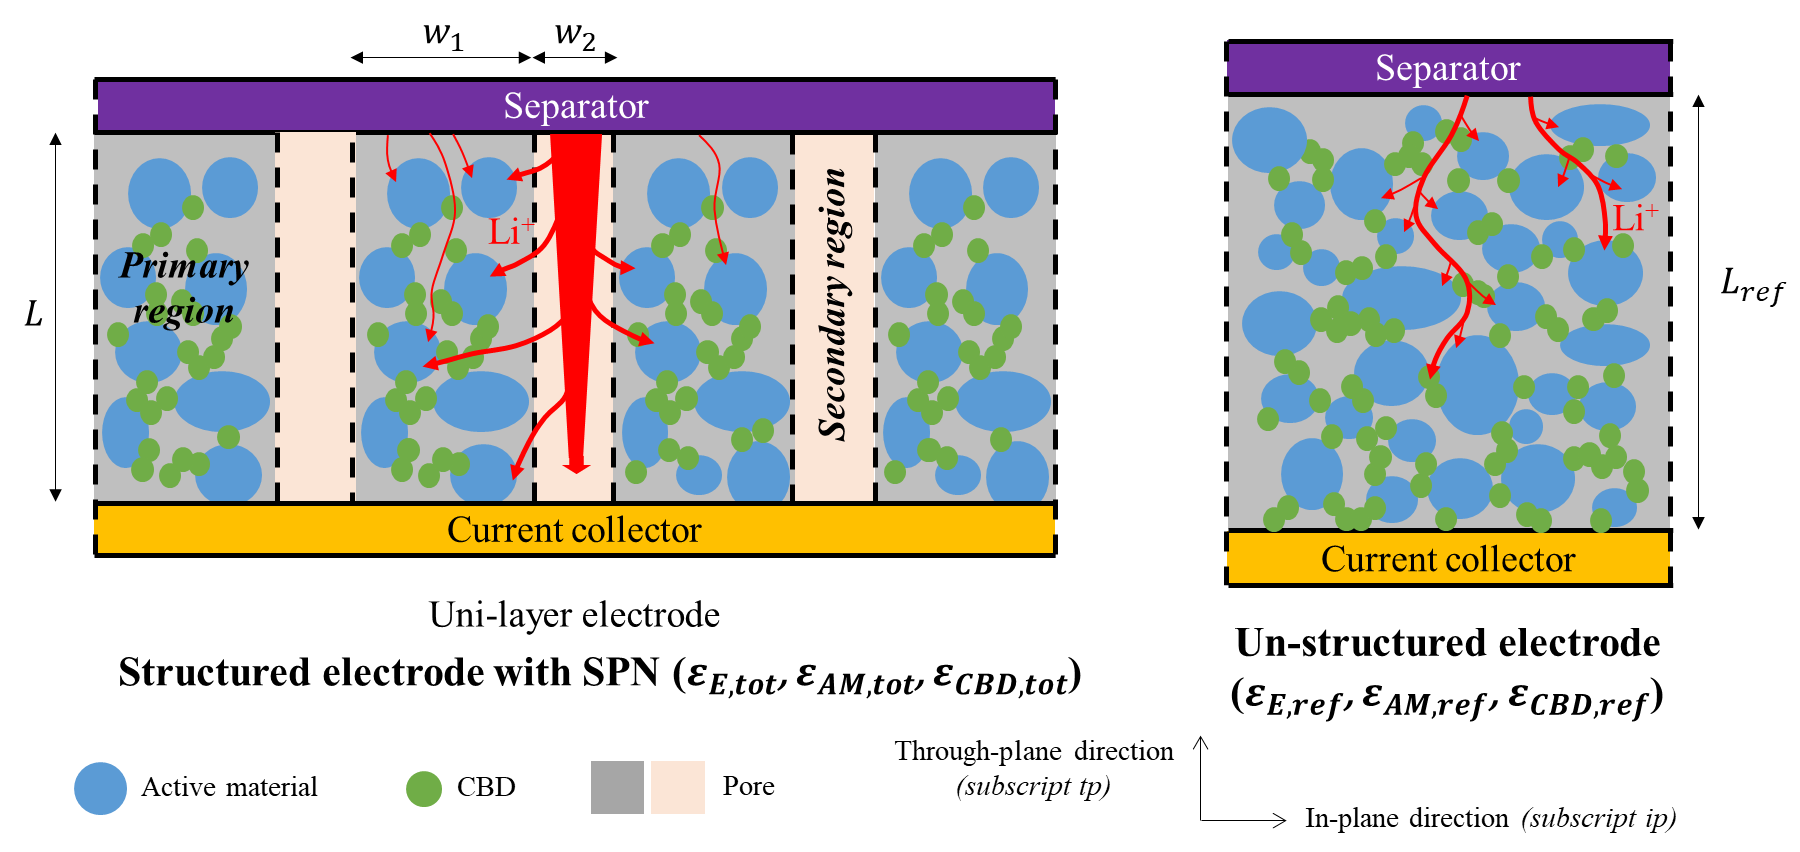

(left) Structured electrode with secondary pore network, (right) reference un-structured electrode.**Both electrode are compared with the same amount of active material, i.e., the same theoritical capacity**. *Lowerscript  '1' and '2' are used for the primary and secondary region, 'tot' and 'ref' for the structured and the reference electrode, 'E', 'AM', and 'CBD' for the electrolyte, the active material and the carbon-binder additives.  Superscript 'tp' and 'ip' are used to indicated through-plane and 'in-plane' directions.*

The model main elements are listed below:

- Because the primary and secondary region are parallel, along the electrode thickness, **the normalized effective through-plane diffusion **$D_{n,tot}^{tp}$** of the structured electrode can be deduced from a simple rule of mixture**: $D_{n,tot}^{tp} =\frac{\sum_{k=1}^2 D_{n,k}^{tp} \times V_k }{\sum_{k=1}^2 V_k }$ with $D_{n,k}^{tp}$ and $V_k$, respectively, the normalized through-plane diffusion coefficient and the volume of the region *k*. Since the secondary region is fully filled with electrolyte, then $D_{n,2}^{tp} =1$. The primary region normalized through-plane diffusion coefficient$D_{n,1}^{tp} \;$is deduced from its through-plane tortuosity factor $\tau_1^{tp}$ and porosity $\varepsilon_{E,1\ }$. The region volume fractions are deduced from the channel shape (rectangular or cylindrical) and the region widths $w_k \ldotp$

- Both the reference and the structured electrode share the same tortuosity-porosity relationship with the same coefficients.

- If the study is done **considering both structured and reference electrode share the same thickness** (i.e., same volumetric and gravimetric specific capacity), then $\varepsilon_{E,1\ }$is lower than the electrode reference porosity $\varepsilon_{E,\textrm{ref}\;}$to accomodate for the increase of total porosity introduced by the secondary pore network. **Alternatively, if the study is done considering both primary region of the structured electrode and reference electrode share the same porosity **(i.e., lower gravimetric and volumetric specific capacity), then the structured electrode is thicker, which will increase the characteristic diffusion time. The second case is only relevant if the battery system is not constrained by volume or mass.

- The **additives** (carbon-black binder, noted CBD) are considered and impact the calculation of the tortuosity factor. CBD volume fraction is set as a constant ratio of the active material volume fraction.

- **Diffusion anisotropy** is considered, i.e. in-plane ionic and through-plane tortuosity factor can be different, as many LIB electrodes are not isotropic. 

At constant thickness, the primary region porosity is reduced to preserve the volumetric and gravimetric specific capacity, thus providing a meaninfgul comparison with the reference electrode. Therefore, while the motivation of adding a coarse secondary pore network to the electrode microstructure consist in improving the through-plane diffusion coefficient,** it will also degrade the diffusion within the fine pore network of the primary region due to the induced lower porosity, **eventually triggering transport limitation. Especially, it is important to keep high enough the primary region in-plane diffusion $D_{n,1}^{ip}$ so that lithium ions will still have access to the active material at the center of the primary region. With this restriction in mind, three optimization objectives are considered, for which optimal design parameters are calculated:

- Maximize the product of the electrode through-plane diffusion gain $D_{tot,g}^{tp} =\frac{D_{n,tot}^{tp} }{D_{n,ref}^{tp} }>1\$(improved by SPN) with the primary region in-plane diffusion gain $D_{1,g}^{ip} =\frac{D_{n,1}^{ip} }{D_{n,ref}^{ip} }<1\$(degraded by SPN). 

- Enforce diffusion isotropy between the electrode through-plane diffusion coefficient and the primary region in-plane diffusion coefficient, i.e., $\frac{D_{n,tot}^{tp} }{D_{n,1}^{ip} }=1$. This objective aims to balance the diffusion, preventing to excessively favor one direction over the other, *without considering *diffusion distance.

- Enforce isotropy between the electrode through-plane characteristic diffusion time $t_{tot}^{tp}$ and the primary region in-plane characteristic diffusion time $t_1^{ip}$, i.e., $\frac{t_{tot}^{tp} }{t_1^{ip} }=1$. Characteristic diffusion time is the ratio between the square of a characteristic diffusion distance and the diffusion coefficient. In this case, the electrode through-plane diffusion distance is the electrode thickness $L$ and the primary region in-plane diffusion distance is half the region width $w_1$, which implies: $\frac{D_{n,tot}^{tp} }{D_{n,1}^{ip} }=\frac{4\times L^2 }{{w_1 }^2 }$.  This objective aims to balance the diffusion, preventing to excessively favor one direction over the other, *considering *diffusion distance.

The analytical model must be considered as **a pre-screening tool** to quickly investigate large design space, that can be refined later with a more complex (electrochemical) but also more CPU-expensive numerical model. Besides, it is used to identify analytically the expression of the releavant design parameters.

# Parameters

***Instructions:***

*Some parameters can be defined with both a minimum and a maximum to investigate a larger parameter space. The grid resolution indicates the number of intermediate values considered in the model for a given parameter between the two bounds. You can ignore the grid resolution value if you set minimum equals to maximum. You can investigate different combinations of variable parameters. However to be able to plot 2D design space map, there is a limitation of the number of variables parameters:*

- *To plot 2D map of the optimal SPN design parameter related with 1st optimization objective: you can select ****0, 1 or 2 variable parameter among ***$\varepsilon_{E,\textrm{ref}}$**,**$\gamma$**, and **$\alpha$ ***in addition to ***$R_V$. The tortuosity factor anisotropy $\tau^{\textrm{tp}/\textrm{ip}} =\frac{\tau^{\textrm{tp}} }{\tau^{\textrm{ip}} }$  is not considered for this optimiztion objective.

- *To plot 2D map of the optimal SPN design parameter related with 2nd or 3rd optimization objectives: you can select ****0,1 or 2 variables parameters among ***$\varepsilon_{E,\textrm{ref}}$**,**$\gamma$**, **$\alpha$, $\tau^{\textrm{tp}/\textrm{ip}}$, and $R_t$*** in addition to ***$R_V$.

*Note that you may need to set a fine grid resolution for *$R_V$* or *$R_w$* in order to find their optimal values.*

## Reference electrode volume fractions

Set the porosity of the reference electrode $\varepsilon_{E,\textrm{ref}}$.

eref_min =0.2; eref_max = 0.4;n_eps=200;

Choose the carbon-binder solid ratio $k$ used for both the reference electrode and the primary region, defined as: $\varepsilon_{\textrm{CBD}} =k\times \varepsilon_{\textrm{AM}}$. 

If you do not want to consider carbon-binder domain, choose $k=0$.

kCBD=0;

## Tortuosity factor coefficients

Set the through-plane tortuosity-porosity coefficients used both for the primary region and the reference electrode.

If you do not want to consider Carbon-binder domain, set $a=0$ and $b=1$. Example of relevant parameters can be found in table 4 of the artice mentioned in the Authors section.


$$\tau_1^{\mathrm{tp}} =\left(a\times \varepsilon_{E,1} +b\right)\times \gamma \times {\left(\varepsilon_{E,1} +\varepsilon_{\mathrm{CBD},1} \right)}^{1-\alpha }$$


a=0;
b=1;
if kCBD==0
    a=0; b=1; % Overwrite
end
gamma_min =1.92; gamma_max =1.92;n_gamma=200;
alpha_min =2; alpha_max =2;n_alpha=200;

You can also set the tortuosity factor anisotropy $\tau^{\textrm{tp}/\textrm{ip}} =\frac{\tau^{\textrm{tp}} }{\tau^{\textrm{ip}} }$.

aniso_min =2.471; aniso_max =2.471; n_aniso=200;

## Secondary pore network parameters

Two different channel geometries, rectangular or cylindrical, are modeled as depicted by the image below (top-bottom view). 

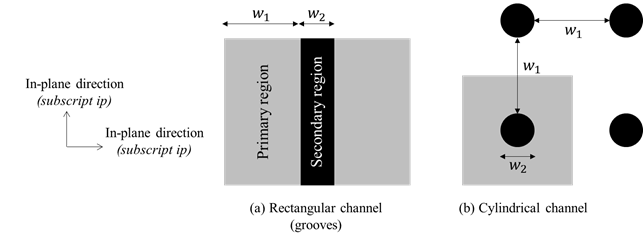

The volume of each region, which are the weights of the rule of mixture used to calculate the effective through-plane diffusion coefficient, depend on the channel geometry:


$$V_1 =A_1 \times L\ \mathrm{w}\mathrm{i}\mathrm{t}\mathrm{h}{\ A}_1 =\ \left\lbrace \begin{array}{cc}
w_{1\ } \times W\times n & \mathrm{i}\mathrm{f}\mathrm{\ }\mathrm{c}\mathrm{h}\mathrm{a}\mathrm{n}\mathrm{n}\mathrm{e}\mathrm{l}\mathrm{s}\mathrm{\ }\mathrm{a}\mathrm{r}\mathrm{e}\mathrm{\ }\mathrm{r}\mathrm{e}\mathrm{c}\mathrm{t}\mathrm{a}\mathrm{n}\mathrm{g}\mathrm{u}\mathrm{l}\mathrm{a}\mathrm{r}\\
{{\left(w_1 +w_2 \right)}}^2 \times n^2 -A_2  & \mathrm{i}\mathrm{f}\mathrm{\ }\mathrm{c}\mathrm{h}\mathrm{a}\mathrm{n}\mathrm{n}\mathrm{e}\mathrm{l}\mathrm{s}\mathrm{\ }\mathrm{a}\mathrm{r}\mathrm{e}\mathrm{\ }\mathrm{c}\mathrm{y}\mathrm{l}\mathrm{i}\mathrm{n}\mathrm{d}\mathrm{r}\mathrm{i}\mathrm{c}\mathrm{a}\mathrm{l}
\end{array}\right.$$



$$V_2 =A_2 \times L\ \mathrm{w}\mathrm{i}\mathrm{t}\mathrm{h}\ {\ A}_2 =\left\lbrace \begin{array}{cc}
w_{2\ } \times W\times {\left(n-1\right)} & \mathrm{i}\mathrm{f}\mathrm{\ }\mathrm{c}\mathrm{h}\mathrm{a}\mathrm{n}\mathrm{n}\mathrm{e}\mathrm{l}\mathrm{s}\mathrm{\ }\mathrm{a}\mathrm{r}\mathrm{e}\mathrm{\ }\mathrm{r}\mathrm{e}\mathrm{c}\mathrm{t}\mathrm{a}\mathrm{n}\mathrm{g}\mathrm{u}\mathrm{l}\mathrm{a}\mathrm{r}\\
\pi \times {{\left(\frac{w_2 }{2}\right)}}^2 \times n^2  & \mathrm{i}\mathrm{f}\mathrm{\ }\mathrm{c}\mathrm{h}\mathrm{a}\mathrm{n}\mathrm{n}\mathrm{e}\mathrm{l}\mathrm{s}\mathrm{\ }\mathrm{a}\mathrm{r}\mathrm{e}\mathrm{\ }\mathrm{c}\mathrm{y}\mathrm{l}\mathrm{i}\mathrm{n}\mathrm{d}\mathrm{r}\mathrm{i}\mathrm{c}\mathrm{a}\mathrm{l}
\end{array}\right.$$


With $w_{1\ }$and $w_2$ the width,$V_1$ and $V_2$ the volume, and${\ A}_1$and${\ A}_2$ the in-plane area, of respectively the primary and secondary region. The electrode thickness is noted $L$.

The electrode dimension normal to 1st and 2nd figures' system of axis is noted *W*. The model is insensitive with *W* as it simplifies with volume region ratio. The number of primary regions is noted *n* while we consider the electrode in-plane extremities are primary regions.Its value is chosen extremely high to consider a full-size electrode. Because of this, model results are insensitive with *n* as it simplifies with volume region ratio. 

Channel_geometry = "Rectangular";

You can choose to control the channel dimension with the secondary region volume fraction $R_V$ or with the secondary region width to primary region width ratio $R_w$ defined as:

$R_V =\frac{V_2 }{V_1 +V_2 }$ and $R_w =\frac{w_2 }{w_1 }$

R_choice="Rv";
R_min =0;
R_max =0.4;
n_R=200;

Lastly, you can control the width-to-thickness ratio of primary region $R_t$ defined as:


$$R_t =\frac{w_1 }{L}$$


Rt_min =0.01;
Rt_max =2;
n_RT=20;

Note that this ratio is only used in regards with the third optimization objectives (enforcing  isotropic characteristic diffusion time).

## Uni-layer or bi-layer

Structured electrodes exist in two variants: without (uni-layer case) or with (bi-layer case) a small pad of porous electrode without SPN at the base of the current collector side. The default utlisation of this model is uni-layer as there is no analytical method to calculate in a unique way the effective through plane diffusion coefficient of this structure (combination of layers in parallel and in series). Although you can still investigate bi-layer case but results will be bounded. The characteristic through-plane diffusion time is $L+L_a$.

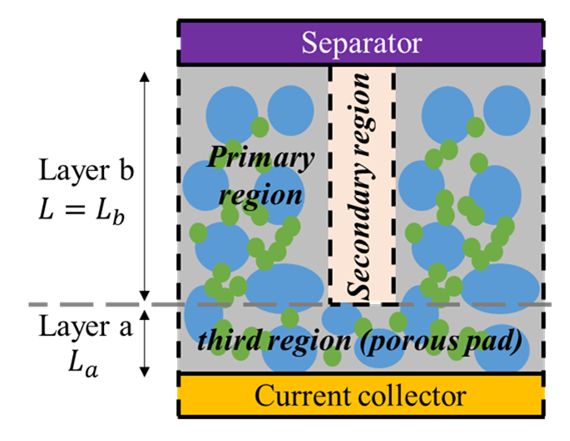

You can control the bi-layer case adjusting the primary region thickness ratio $R_L$, defined as:


$$R_L =\frac{L}{L+L_a }$$


RL=1;

Set $R_L =1$ to model the uni-layer case.

## Comparison with reference electrode

To provide a meaningful comparison, electrode with and without SPN must be compared at same theoretical capacity, which implies the mass of active materials must be identical:


$$\frac{A_{\textrm{ref}} \times L_{\textrm{ref}} }{A_1 \times L+\left(\left(A_1 +A_2 \right)\times L_a \right)}=\frac{\varepsilon_{\textrm{AM},1} }{\varepsilon_{\textrm{AM},\textrm{ref}} }$$


Considering both unstructured and structured electrode share the same area (i.e., $A_{\textrm{ref}} =A_1 +A_2$), then two approaches are possible. First, keeping the same electrode volume (and thus thickness) but densifying the primary region to compensate for the total porosity increase induced by the pore channels: $L+L_a =L_{\textrm{ref}} \;$and $\varepsilon_{\textrm{AM},1} >\varepsilon_{\textrm{AM},\textrm{ref}}$. This case preserves the theoretical volumetric and gravimetric specific capacity. Second, keeping the same porosity within the porous matrix but increasing the electrode volume: $\varepsilon_{\textrm{AM},1} =\varepsilon_{\textrm{AM},\textrm{ref}}$ and $L+L_a >L_{\textrm{ref}}$. This case degrades both theoretical gravimetric and volumetric specific capacity, as for the same mass of active material, the electrolyte mass and the electrode volume increases.

If you choose to compare the reference and structured electrode at the same thickness, you should choose a maximum $R_V$ lower than the reference electrode porosity $\varepsilon_{\textrm{ref}}$.

Comparison_choice="Thickness_constant";

## Sintered (fully dense) primary region - simplified model

Freeze casting manufacturing process can be followed by a sintering step, resulting in a densification of the primary region. The extreme case correponds to a fully dense primary region. In such case, there is no more ionic diffusion within the primary region and the active electrochemical interface is only at the interface primary secondary region. SPN will still improve the ionic through-plane diffusion but hinder the in-plane solid state diffusion, 

Only 6 parameters are requried: the primary region width $w_1$, the secondary region width $w_2 ,$ the channel geometry, the electrode thickness $L$, the bulk solid state diffusion coefficient $D_0^S$, and the bulk electrolyte diffusion coefficient $D_0^E$. 

Sintered_case=false;

You can ignore parameters below if you did not check the box above.


Sintered_w1_min =2.5; Sintered_w1_max =10;
Sintered_w2_min =2.5; Sintered_w2_max =10;
Sintered_L_min  =100; Sintered_L_max  =100;
Sintered_Dos=3e-15;
Sintered_Doe=1.35e-10;

# Run model

 

disp 'Code is running...';

Code is running...


tic % Start time
if Sintered_case
    [w1,n_w1]=allvalues(Sintered_w1_min,Sintered_w1_max,250);
    [w2,n_w2]=allvalues(Sintered_w2_min,Sintered_w2_max,150);
    [L,n_L]=allvalues(Sintered_L_min,Sintered_L_max,200);
    w1=w1*1e-6; w2=w2*1e-6; L=L*1e-6; % Conversion um -> m
    time_diffusion_tp_ip = zeros(n_w1,n_w2,n_L); % Characteristic diffuion time ratio
    w2_optimal = zeros(n_w1,n_L);
    n=1e6;
    for k_w1=1:1:n_w1
        time_diffusion_ip = w1(k_w1)^2 / (4*Sintered_Dos);
        for k_w2=1:1:n_w2
            if strcmp(Channel_geometry,"Rectangular")
                A1 = w1(k_w1)*n;
                A2 = w2(k_w2)*(n-1);
            elseif strcmp(Channel_geometry,"Cylindrical")
                A2 = pi*(w2(k_w2)/2)^2*n;
                A1 = (w1(k_w1)+w2(k_w2))^2*n-A2;
            end
            D_eff_tp = ( 0 * A1 + Sintered_Doe * A2) ./ (A1+A2);
            for k_L=1:1:n_L
                time_diffusion_tp = L(k_L)^2 / D_eff_tp;
                time_diffusion_tp_ip(k_w1,k_w2,k_L) = time_diffusion_tp / time_diffusion_ip;
            end
        end
        for k_L=1:1:n_L
            w2_optimal(k_w1,k_L) = interp1(time_diffusion_tp_ip(k_w1,:,k_L),w2,1,"linear");
        end
    end
    
else
    % Volume fraction of reference electrode
    [eref,n_eps]=allvalues(eref_min,eref_max,n_eps);
    eamref = (1-eref)./(1+kCBD);
    ecbdref = kCBD.*eamref;

    % Rv, Rw
    if strcmp(R_choice,"Rv")
        [Rv,n_R]=allvalues(R_min,R_max,n_R);
        if min(Rv)<0 || max(Rv)>1
            error('User-parameter error: by definition, Rv must be >0 and <1. Program will stop')
        end
        if Rv(1)~=0 % Add reference case
            Rv=[0 Rv]; n_R=n_R+1;
        end
        [Rw, A1, A2] = Deduce_Rw_from_Rv(Rv,Channel_geometry);
    elseif strcmp(R_choice,"Rw")
        [Rw,n_R]=allvalues(R_min,R_max,n_R);
        if min(Rw)<0
            error('User-parameter error: by definition, Rw must be >0. Program will stop')
        end
        if Rw(1)~=0 % Add reference case
            Rw=[0 Rw]; n_R=n_R+1;
        end
        [Rv, A1, A2] = Deduce_Rv_from_Rw(Rw,Channel_geometry);
    end
    
    % Deduce layer thickness
    Lref = 1;
    if strcmp(Comparison_choice,"Thickness_constant")
        L = Lref / ( 1+ (1-RL)/RL) * ones(1,n_R);
    elseif strcmp(Comparison_choice,"Porosity_constant")
        L=zeros(1,n_R);
        for k=1:1:n_R
            L(k) =  (A1(k)+A2(k)).*Lref ./ (A1(k) + (A1(k)+A2(k)).*(1-RL)./RL);
        end
    end

    % Second layer thickness
    La = L.*(1-RL)./RL;
    % Region volume
    V1 = A1.*L;
    V2 = A2.*L;
    % Deduce primary region active material volume fractions
    eam1 = zeros(n_R,n_eps);
    for k=1:1:n_R
        eam1(k,:) = (eamref.*(V1(k)+V2(k))*Lref) ./ ((V1(k).*L(k))+(V1(k)+V2(k)).*La(k));
    end
    
    % Deduce primary region volume fractions
    eam1(eam1>1)=NaN; eam1(eam1<0)=NaN;
    ecbd1 = eam1.*kCBD;
    ecbd1(ecbd1>1)=NaN; ecbd1(ecbd1<0)=NaN;
    ee1 = 1-eam1-ecbd1;
    ee1(ee1>1)=NaN; ee1(ee1<0)=NaN;
    
    % Tortuosity factor of reference electrode
    [gamma,n_gamma]=allvalues(gamma_min,gamma_max,n_gamma);
    [alpha,n_alpha]=allvalues(alpha_min,alpha_max,n_alpha);
    [aniso,n_aniso]=allvalues(aniso_min,aniso_max,n_aniso);
    tau_ref_tp = zeros(n_R,n_eps,n_gamma,n_alpha);
    for kg=1:1:n_gamma
        for ka=1:1:n_alpha
            tau_ref_tp(1,:,kg,ka) = tortuosity_factor(a,b,alpha(ka),gamma(kg),eref,ecbdref);
        end
    end
    for kr=2:1:n_R
        tau_ref_tp(kr,:,:,:) = tau_ref_tp(1,:,:,:);
    end
    tau_ref_ip = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for k=1:1:n_aniso
        tau_ref_ip(:,:,:,:,k) = tau_ref_tp(:,:,:,:)./aniso(k);
    end
    
    % Normalized diffusion coefficient of reference electrode
    D0=1;
    Dn_ref_tp = zeros(n_R,n_eps,n_gamma,n_alpha);
    Dn_ref_ip = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for k=1:1:n_eps
        Dn_ref_tp(:,k,:,:) = eref(k)./tau_ref_tp(:,k,:,:) .* D0;
        Dn_ref_ip(:,k,:,:,:) = eref(k)./tau_ref_ip(:,k,:,:,:) .* D0;
    end
    
    % Tortuosity factor of primary region
    tau_1_tp = zeros(n_R,n_eps,n_gamma,n_alpha);
    for kg=1:1:n_gamma
        for ka=1:1:n_alpha
            tau_1_tp(:,:,kg,ka) = tortuosity_factor(a,b,alpha(ka),gamma(kg),ee1(:,:),ecbd1(:,:));
        end
    end
    tau_1_ip = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for k=1:1:n_aniso
        tau_1_ip(:,:,:,:,k) = tau_1_tp(:,:,:,:)./aniso(k);
    end
    
    % Normalized diffusion coefficient of primary region
    Dn_1_tp = zeros(n_R,n_eps,n_gamma,n_alpha);
    Dn_1_ip = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for kg=1:1:n_gamma
        for ka=1:1:n_alpha
            Dn_1_tp(:,:,kg,ka) = ee1(:,:)./tau_1_tp(:,:,kg,ka) .* D0;
            for kan=1:1:n_aniso
                Dn_1_ip(:,:,kg,ka,kan) = ee1(:,:)./tau_1_ip(:,:,kg,ka,kan) .* D0;
            end
        end
    end
    
    Dn_1_ip2 = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for ke=1:1:n_eps
        for kr=1:1:n_R
            for kg=1:1:n_gamma
                for ka=1:1:n_alpha
                    for kan=1:1:n_aniso
                        Dn_1_ip2(kr,ke,kg,ka,kan) = ee1(kr,ke)./tau_1_ip(kr,ke,kg,ka,kan) .* D0;
                    end
                end
            end
        end
    end
    
    % Effecive through plane normalized diffusion coefficient of electrode
    Dn_tot_tp_b = zeros(n_R,n_eps,n_gamma,n_alpha);
    for ke=1:1:n_eps
        for kg=1:1:n_gamma
            for ka=1:1:n_alpha
                Dn_tot_tp_b(:,ke,kg,ka) = (V1(:) .* Dn_1_tp(:,ke,kg,ka) + V2(:) .* 1) ./ (V1(:) + V2(:));
            end
        end
    end
    
    % Bi-layer case
    V3 = (A1+A2).*La;
    Dn_tot_tp_star = zeros(n_R,n_eps,n_gamma,n_alpha);
    Dn_tot_tp_star2 = zeros(n_R,n_eps,n_gamma,n_alpha);
    for ke=1:1:n_eps
        for kg=1:1:n_gamma
            for ka=1:1:n_alpha
                Dn_tot_tp_star(:,ke,kg,ka)  = (V1(:) + V2(:) + V3(:)) ./ ( (V1(:) + V2(:))./Dn_tot_tp_b(:,ke,kg,ka) + V3(:)./Dn_1_tp(:,ke,kg,ka) );
                Dn_23_tp = (V2(:) + A2(:).*La(:)) ./ ( V2(:)./1 + A2(:).*La(:)./Dn_1_tp(:,ke,kg,ka) );
                Dn_tot_tp_star2(:,ke,kg,ka) = (Dn_1_tp(:,ke,kg,ka).*A1(:) + Dn_23_tp.*A2(:)) ./ (A1(:) + A2(:));
            end
        end
    end
    clear Dn_23_tp
    Dn_tot_tp_star2(1,:,:,:) = Dn_tot_tp_star(1,:,:,:); % Replace NaN
    
    % Total volume fraction of structured electrode
    eetot=zeros(n_R,n_eps);
    eamtot=zeros(n_R,n_eps);
    ecbdtot=zeros(n_R,n_eps);
    for k=1:1:n_R
        eetot(k,:) = (ee1(k,:).*V1(k) + 1.*V2(k) + ee1(k,:).*V3(k)) ./ (V1(k) + V2(k) + V3(k));
        eeb(k,:) = (ee1(k,:).*V1(k) + 1.*V2(k)) ./ (V1(k) + V2(k));
        eamtot(k,:) = (eam1(k,:).*V1(k) + 0.*V2(k) + eam1(k,:).*V3(k)) ./ (V1(k) + V2(k) + V3(k));
        ecbdtot(k,:) = (ecbd1(k,:).*V1(k) + 0.*V2(k) + ecbd1(k,:).*V3(k)) ./ (V1(k) + V2(k) + V3(k));
    end
    
    % Tortuosity factor of the structured electrode
    tau_tot_tp_b = zeros(n_R,n_eps,n_gamma,n_alpha);
    tau_tot_tp_star = zeros(n_R,n_eps,n_gamma,n_alpha);
    tau_tot_tp_star2 = zeros(n_R,n_eps,n_gamma,n_alpha);
    for kg=1:1:n_gamma
        for ka=1:1:n_alpha
            tau_tot_tp_b(:,:,kg,ka) = eeb(:,:) .*D0 ./ Dn_tot_tp_b(:,:,kg,ka);
            tau_tot_tp_star(:,:,kg,ka) = eetot(:,:) .*D0 ./ Dn_tot_tp_star(:,:,kg,ka);
            tau_tot_tp_star2(:,:,kg,ka) = eetot(:,:) .*D0 ./ Dn_tot_tp_star2(:,:,kg,ka);
        end
    end
    
    % Optimization objective 1: maximize diffusion gain product
    D_tot_g_tp_star = Dn_tot_tp_star ./ Dn_ref_tp; % >1
    D_tot_g_tp_star2 = Dn_tot_tp_star2 ./ Dn_ref_tp; % >1
    %D_tot_g_tp_star2(1,:,:,:) = D_tot_g_tp_star(1,:,:,:); % Replace NaN
    tau_tot_g_tp_star = tau_tot_tp_star ./ tau_ref_tp; % <1
    tau_tot_g_tp_star2 = tau_tot_tp_star ./ tau_ref_tp; % <1
    D_1_g_ip = Dn_1_ip ./ Dn_ref_ip; % <1
    tau_1_g_ip = tau_1_ip ./ tau_ref_ip; % >1
    D_1_g_tp = Dn_1_tp ./ Dn_ref_tp; % <1
    tau_1_g_tp = tau_1_tp ./ tau_ref_tp; % >1
    gain_product_star = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    gain_product_star2 = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for kan=1:1:n_aniso
        gain_product_star(:,:,:,:,kan) = D_tot_g_tp_star(:,:,:,:) .* D_1_g_ip(:,:,:,:,kan);
        gain_product_star2(:,:,:,:,kan) = D_tot_g_tp_star2(:,:,:,:) .* D_1_g_ip(:,:,:,:,kan);
    end
    
    % Find optimal ratio
    max_gain_star = zeros(n_eps,n_gamma,n_alpha,3); % 1 max,2 index max,3 index unity
    max_gain_star2 = zeros(n_eps,n_gamma,n_alpha,3);
    for ke=1:1:n_eps
        for kg=1:1:n_gamma
            for ka=1:1:n_alpha
                max_gain_star(ke,kg,ka,1) = max(gain_product_star(:,ke,kg,ka));
                max_gain_star(ke,kg,ka,2) = find(gain_product_star(:,ke,kg,ka)==max_gain_star(ke,kg,ka,1));                
                % Interpolate index, to avoid need of an excessive grid resolution
                obj_=1;
                xa_ = gain_product_star(:,ke,kg,ka);
                va_ = [1:1:n_R];
                id_nan = find(isnan(xa_));
                xa_(id_nan)=[]; va_(id_nan)=[]; xa_(1)=-9e9; % Remove trivial case Rv=0
                max_gain_star(ke,kg,ka,3) = interp1(xa_,va_,obj_,'linear');

                max_gain_star2(ke,kg,ka,1) = max(gain_product_star2(:,ke,kg,ka));
                max_gain_star2(ke,kg,ka,2) = find(gain_product_star2(:,ke,kg,ka)==max_gain_star2(ke,kg,ka,1));                
                % Interpolate index, to avoid need of an excessive grid resolution
                obj_=1;
                xa_ = gain_product_star2(:,ke,kg,ka);
                va_ = [1:1:n_R];
                id_nan = find(isnan(xa_));
                xa_(id_nan)=[]; va_(id_nan)=[]; xa_(1)=-9e9; % Remove trivial case Rv=0
                max_gain_star2(ke,kg,ka,3) = interp1(xa_,va_,obj_,'linear');
            end
        end
    end
    
    % Optimization objective 2 (diffusion coefficient isotropy) and 3 (characteristic diffusion time isotropy)
    D_ratio_star = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    D_ratio_star2 = zeros(n_R,n_eps,n_gamma,n_alpha,n_aniso);
    for kan=1:1:n_aniso
        D_ratio_star(:,:,:,:,kan) = Dn_tot_tp_star(:,:,:,:) ./ Dn_1_ip(:,:,:,:,kan);
        D_ratio_star2(:,:,:,:,kan) = Dn_tot_tp_star2(:,:,:,:) ./ Dn_1_ip(:,:,:,:,kan);
    end
    % Find optimal ratio
    D_ratio_opt2_star = zeros(n_eps,n_gamma,n_alpha,n_aniso); % index unity
    D_ratio_opt2_star2 = zeros(n_eps,n_gamma,n_alpha,n_aniso);       
    % Rt
    [Rt,n_RT]=allvalues(Rt_min,Rt_max,n_RT);    
    D_ratio_opt3_star = zeros(n_eps,n_gamma,n_alpha,n_aniso,n_RT); % index for 4/(Rt*Rt)
    D_ratio_opt3_star2 = zeros(n_eps,n_gamma,n_alpha,n_aniso,n_RT);
    for ke=1:1:n_eps
        for kg=1:1:n_gamma
            for ka=1:1:n_alpha
                for kan=1:1:n_aniso
                    obj_2 = 1;
                    
                    % Interpolate index, to avoid need of an excessive grid resolution
                    xa_ = D_ratio_star(:,ke,kg,ka,kan);
                    va_ = [1:1:n_R];
                    id_nan = find(isnan(xa_));
                    xa_(id_nan)=[]; va_(id_nan)=[];
                    D_ratio_opt2_star(ke,kg,ka,kan) = interp1(xa_,va_,obj_2,'linear');
                    
                    xb_ = D_ratio_star2(:,ke,kg,ka,kan);
                    vb_ = [1:1:n_R];
                    id_nan = find(isnan(xb_));
                    xb_(id_nan)=[]; vb_(id_nan)=[];                    
                    D_ratio_opt2_star2(ke,kg,ka,kan) = interp1(xb_,vb_,obj_2,'linear');
                    
                    for krt=1:1:n_RT
                        %obj_3 = 4/(Rt(krt)^2); % uni-layer case
                        obj_3 = 4/(Rt(krt)^2) * (1 + 2*(1-RL)/RL + ((1-RL)/RL)^2 );  % bi-layer case
                        % Interpolate index, to avoid need of an excessive grid resolution
                        D_ratio_opt3_star(ke,kg,ka,kan,krt) = interp1(xa_,va_,obj_3,'linear');
                        D_ratio_opt3_star2(ke,kg,ka,kan,krt) = interp1(xb_,vb_,obj_3,'linear');
                    end
                    
                end
            end
        end
    end
    
    % Verification from analytical equation (simply to ensure we did not make error manipulating array indices)
    if RL==1 % Only for uni-layer case
        for k=1:1:50 % Test multiple times
            ke = randi(n_eps); kr = randi(n_R); ka = randi(n_alpha); kg = randi(n_gamma); kan = randi(n_aniso); % Select random values
            val_g1 = gain_product_star(kr,ke,kg,ka); % Analytical, from evaluating several expressions sequential
            val_r1 = D_ratio_star(kr,ke,kg,ka,kan);
            e_ = eref(ke); r_ = Rv(kr); a_ = alpha(ka); g_ = gamma(kg); an_ = aniso(kan);
            if strcmp(Comparison_choice,"Thickness_constant")
                if kCBD==0 % Note both expression are equivalent
                    val_g2 = ( ((e_-1)/(1-r_)+1)^a_ * (1-r_)/g_ + r_ ) * ( ((e_-1)/(1-r_)+1)^a_ * g_/(e_^(2*a_)) ); % Analytical, final expression
                    val_r2 = ( ((e_-1)/(1-r_)+1)^a_ * (1-r_)/g_ + r_ ) * ( ((e_-1)/(1-r_)+1)^(-a_) * g_/an_ );
                else
                    e1_ = (e_-1)/(1-r_)+1;
                    T_ = (a*e_+b)*g_*((e_+kCBD)/(1+kCBD))^(1-a_);
                    T1_ = (a*e1_+b)*g_*((e1_+kCBD)/(1+kCBD))^(1-a_);
                    val_g2 = (e1_/T1_*(1-r_) + r_)*(e1_/T1_)*((T_/e_)^2);
                    val_r2 = (r_*(T1_/e1_-1)+1)/an_;
                end
            elseif strcmp(Comparison_choice,"Porosity_constant")
                if kCBD==0 % Note both expression are equivalent
                    val_g2 = r_*(g_*e_^(-a_)-1)+1;
                    val_r2 = 1/an_ * (  r_*(g_*e_^(-a_)-1) + 1);
                else
                    T_ = (a*e_+b)*g_*((e_+kCBD)/(1+kCBD))^(1-a_);
                    val_g2 = r_*(T_/e_-1)+1;
                    val_r2 = 1/an_ * (  r_*(T_/e_-1) + 1);
                end
            end
            if abs(val_g1-val_g2)>1e-3 || abs(val_r1-val_r2)>1e-3
                error('Model error')
            end
        end
    end
    
end
toc % Display elapsed time

Elapsed time is 1.887428 seconds.


# Figures options

You can choose to plot results as a function of the secondary region volume fraction $R_V$ or of the secondary region width to primary region width ratio $R_w$.

R_plot="Rv";

Plot in-plane diffusion 'gain' $D_{1,g}^{\textrm{ip}} =\frac{D_{n,1}^{\textrm{ip}} }{D_{n,\textrm{ref}}^{\textrm{ip}} }<1$ or in-plane diffusion 'loss' $D_{1,l}^{\textrm{ip}} =\frac{D_{n,\textrm{ref}}^{\textrm{ip}} }{D_{n,1}^{\textrm{ip}} }>1$. Second choice is interesting to comparing through-plane diffusion gain and in-plane diffusion loss rate.

In_planediffusion_plot="Gain";

If you have selected the bi-layer case, what homogenization approach do you prefer:

bilayer_plot="PS";

Most results are plotted using two-dimensional maps. You can select the number of isolines, and if you want to show isovalues.

n_isolines=10;
show_isovalue_boolean=true;

Figure font:

font_name="Times New Roman";
font_plot_size=10;
Major_grid=true;
Minor_grid=false;

Save options. If you choose to save figures, please enter the folder name in the dedicated field. If the folder does not exisit, it will be created.

save_png=false;
save_fig=false;
save_folder=char("");

# Figures

 
warning('off', 'MATLAB:contour:ConstantData');
scrsz = get(0,'ScreenSize'); % Screen resolution
if length(save_folder)<=1
    save_folder=pwd;
end
if ispc && save_folder(end)~='\'
    save_folder=[save_folder '\'];
end
if ~ispc && save_folder(end)~='/'
    save_folder=[save_folder '/'];
end
if show_isovalue_boolean
    show_isovalue='on';
else
    show_isovalue='off';
end
if save_png || save_png
    if exist(save_folder,'dir')==0 % Folder existence is checked, and created if necessary
        mkdir(save_folder);
    end
    h=fprintf('Figures are saved in: %s',save_folder);
end
if Major_grid
    show_grid = 'on';
else
    show_grid = 'off';
end
if Minor_grid
    show_minorgrid = 'on';
else
    show_minorgrid = 'off';
end

if Sintered_case
    Fig_ = figure; % Create figure
    Fig_.Name= 'Fully dense primary region, sintered extreme case';
    Fig_.Color='white'; % Background colour
    set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/2 scrsz(4)/1.5]);
    ax = axes(Fig_);
    hold(ax,'on');
    if n_L==1
        t_title=title({'Characteristic diffusion time ratio between','electrode through plane (liquid) and primary region in-plane (solid)'}); % - Title
        [X,Y] = meshgrid(w1*1e6,w2*1e6); % Grid
        contourf(X,Y,time_diffusion_tp_ip',n_isolines,'ShowText',show_isovalue)
        ylabel('w_{2} (\mum)');
        xlabel('w_{1} (\mum)');
        colorbar
        h=colorbar(ax);
        ylabel(h, 't_{tot}^{tp} / t_{1}^{ip}');
        plot(w1*1e6,w2_optimal*1e6,'linewidth',2,'Color','k')
    else
        t_title=title({'Channel w_{2} width so that characteristic diffusion time ratio between','electrode through plane (liquid) and primary region in-plane (solid) is isotropic'}); % - Title
        [X,Y] = meshgrid(w1*1e6,L*1e6); % Grid
        contourf(X,Y,(w2_optimal*1e6)',n_isolines,'ShowText',show_isovalue)
        ylabel('L (\mum)');
        xlabel('w_{1} (\mum)');
        colorbar
        h=colorbar(ax);
        ylabel(h, 'w_{2} (\mum) so that t_{tot}^{tp} / t_{1}^{ip} = 1');        
    end
    set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
    set(h,'FontName',font_name,'FontSize',font_plot_size);
    t_title.FontSize=font_plot_size+2;
    hold(ax,'off'); % Release current subplot
    fullpath = [save_folder 'Fully_denseprimaryregion'];
    if save_png
        saveas(Fig_,fullpath,'png')
    end
    if save_fig
        set(Fig_, 'Visible', 'on');
        savefig(Fig_,fullpath)
    end
    
else
    % Grid
    str_eref = 'Reference electrode porosity \epsilon_{E,ref}';
    str_gamma = '\gamma';
    str_alpha = '\alpha';
    str_aniso = '\tau^{tp/ip}';
    str_Rt ='R_{t}';
    if strcmp(R_plot,"Rv")
        [X_epsilon,Y_R] = meshgrid(eref,Rv);
        R_label = 'SPN volume ratio R_{V} = V_{2}/(V_{1}+V_{2})';
        str_sav = 'Rv';
        x_R = Rv;
    elseif strcmp(R_plot,"Rw")
        [X_epsilon,Y_R] = meshgrid(eref,Rw);
        R_label = 'Region width ratio R_{w} = w_{2}/w_{1}';
        str_sav = 'Rw';
        x_R = Rw;
    end
end    

### Volume fractions

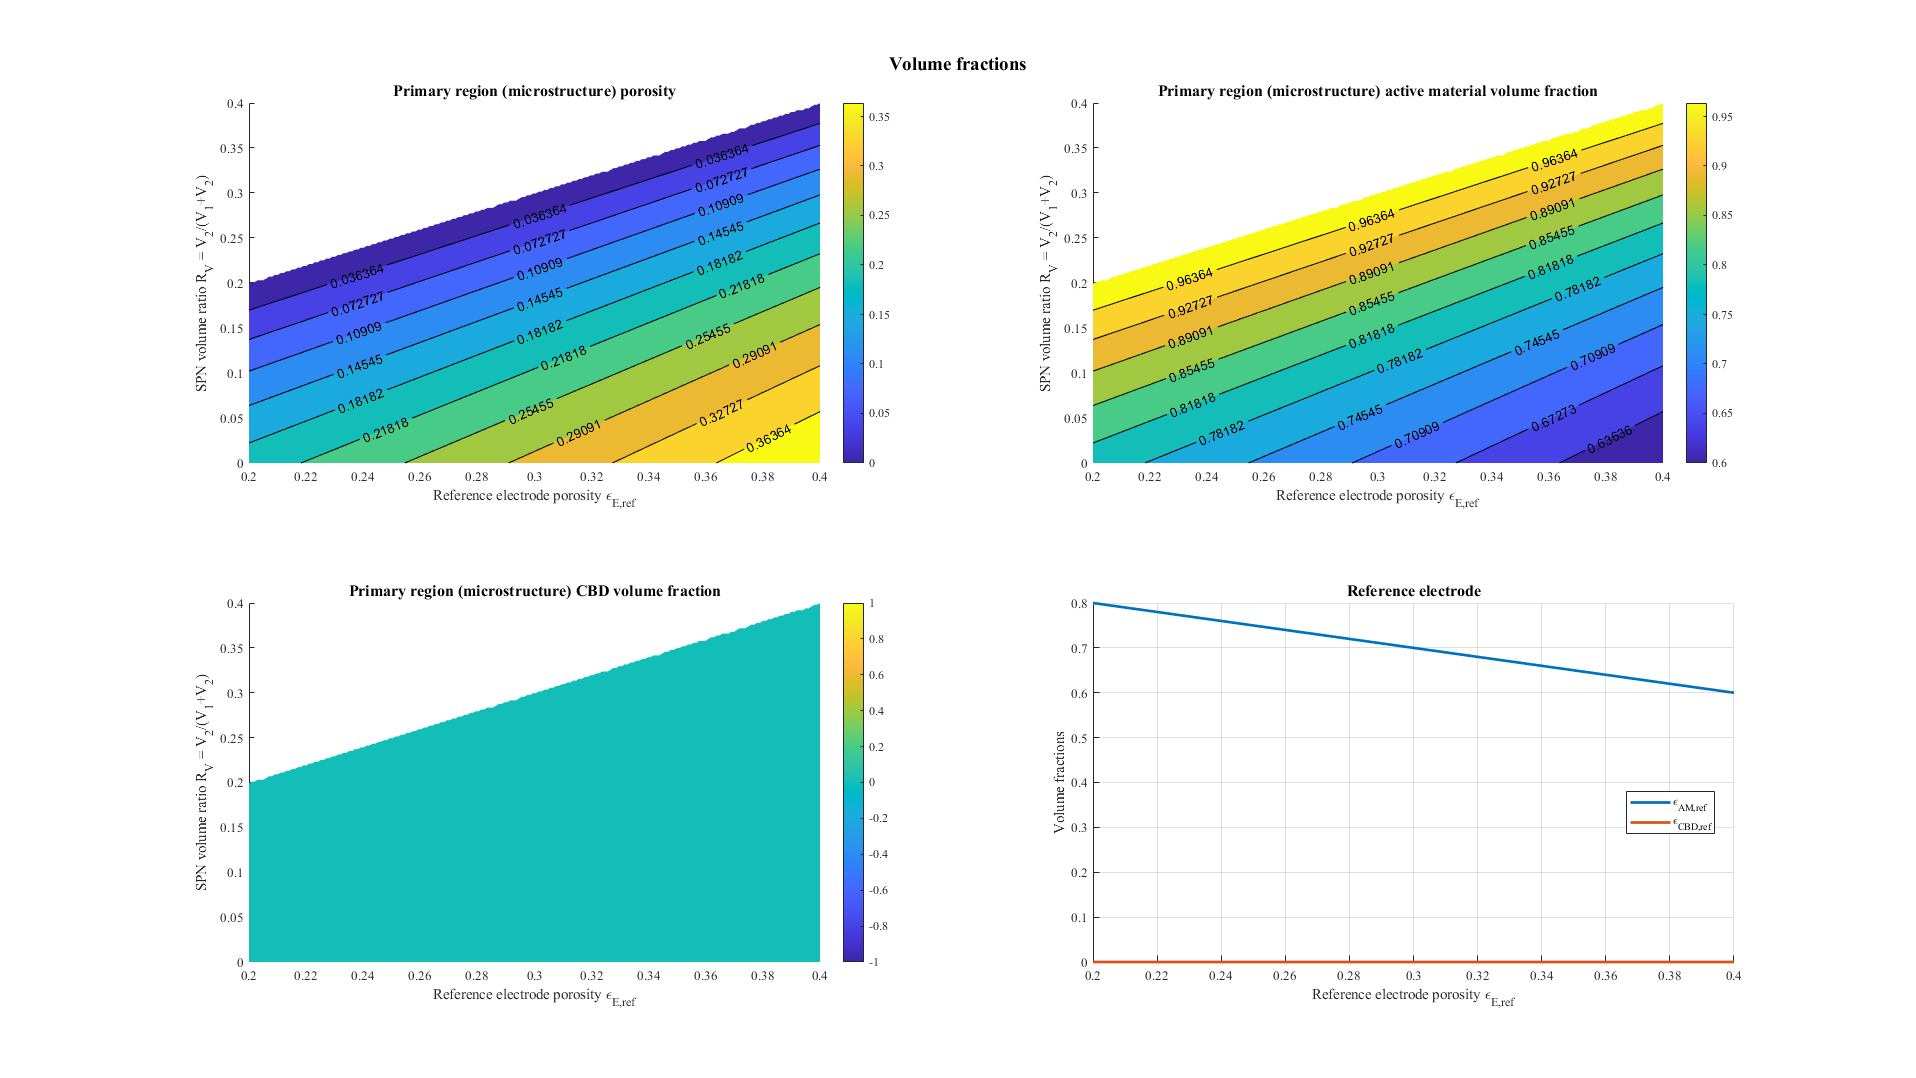

if ~Sintered_case    
    Fig_ = figure; % Create figure
    Fig_.Name= 'Volume fractions';
    Fig_.Color='white'; % Background colour
    if n_eps>1
        set(Fig_,'position',scrsz); % Full screen figure
        for id_axe=1:1:4 % Iterate over axe
            sub_axes=subplot(2,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title('Primary region (microstructure) porosity'); % - Title
                contourf(X_epsilon,Y_R,ee1,n_isolines,'ShowText',show_isovalue)
                ylabel(R_label);
                colorbar
            elseif id_axe==2
                t_title=title('Primary region (microstructure) active material volume fraction'); % - Title
                contourf(X_epsilon,Y_R,eam1,n_isolines,'ShowText',show_isovalue)
                ylabel(R_label);
                colorbar
            elseif id_axe==3
                t_title=title('Primary region (microstructure) CBD volume fraction'); % - Title
                contourf(X_epsilon,Y_R,ecbd1,n_isolines,'ShowText',show_isovalue)
                ylabel(R_label);
                colorbar
            elseif id_axe==4
                t_title=title('Reference electrode'); % - Title
                plot(eref,eamref,'linewidth',2)
                plot(eref,ecbdref,'linewidth',2)
                str_legend = {'\epsilon_{AM,ref}','\epsilon_{CBD,ref}'};
                ylabel('Volume fractions');
                grid(sub_axes,show_grid); % Major Grid
                set(sub_axes,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
                legend(sub_axes,str_legend,'Location','best'); % Legend
            end
            xlabel(str_eref);
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        if RL==1
            sgtitle(Fig_,'Volume fractions','FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        else
            sgtitle(Fig_,['Volume fractions, L/L+L_{a}=' num2str(RL,'%1.2f')],'FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        end
    else
        ax = axes(Fig_);
        hold(ax,'on');
        if RL==1
            t_title=title('Volume fractions','FontWeight','bold','FontSize',font_plot_size+2,'FontName',font_name);
        else
            t_title=title(['Volume fractions, L/L+L_{a}=' num2str(RL,'%1.2f')],'FontWeight','bold','FontSize',font_plot_size+2,'FontName',font_name);
        end
        plot(Y_R,ee1,'linewidth',2)
        plot(Y_R,eam1,'linewidth',2)
        plot(Y_R,ecbd1,'linewidth',2)
        xlabel(R_label);
        ylabel('\epsilon')
        str_legend = {'\epsilon_{E,1}','\epsilon_{AM,1}','\epsilon_{CBD,1}'};
        grid(ax,show_grid); % Major Grid
        set(ax,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
        legend(ax,str_legend,'Location','best'); % Legend
        set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
        t_title.FontSize=font_plot_size+2;
        hold(ax,'off'); % Release current subplot
    end
    if RL==1
        filename= ['Primary_region_porosity_' char(Channel_geometry) '_' str_sav]; % Save figure
    else
        filename= ['Primary_region_porosity_RL' num2str(100*RL,'%1.0f') '_' char(Channel_geometry) '_' str_sav]; % Save figure
    end
    fullpath = [save_folder filename];
    if save_png
        saveas(Fig_,fullpath,'png')
    end
    if save_fig
        set(Fig_, 'Visible', 'on');
        savefig(Fig_,fullpath)
    end
end

### Electrode thickness

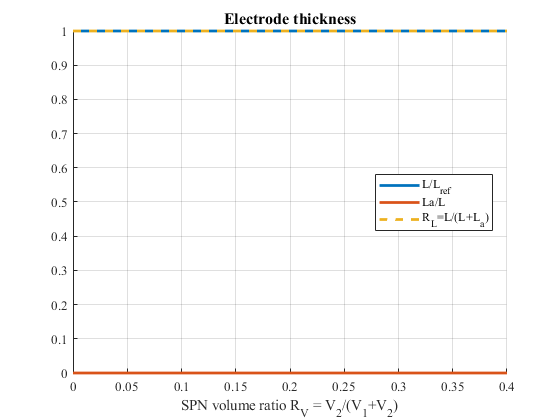

if ~Sintered_case 
    Fig_ = figure; % Create figure
    Fig_.Name= 'Electrode thickness';
    Fig_.Color='white'; % Background colour
    ax = axes(Fig_);
    hold(ax,'on');
    t_title=title('Electrode thickness'); % - Title
    plot(x_R,L./Lref,'linewidth',2)
    plot(x_R,La./Lref,'linewidth',2)
    plot(x_R,RL*ones(1,n_R),'linewidth',2,'LineStyle','--')
    str_legend = {'L/L_{ref}','La/L','R_{L}=L/(L+L_{a})'};
    grid(ax,show_grid); % Major Grid
    set(ax,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
    legend(ax,str_legend,'Location','best'); % Legend
    xlabel(R_label);
    set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
    t_title.FontSize=font_plot_size+2;
    hold(ax,'off');
    if RL==1
        filename= ['Electrode_thickness_' char(Channel_geometry) '_' str_sav]; % Save figure
    else
        filename= ['Electrode_thickness_RL' num2str(100*RL,'%1.0f') '_' char(Channel_geometry) '_' str_sav]; % Save figure
    end
    fullpath = [save_folder filename];
    if save_png
        saveas(Fig_,fullpath,'png')
    end
    if save_fig
        set(Fig_, 'Visible', 'on');
        savefig(Fig_,fullpath)
    end
end

### Reference electrode tortuosity and normalized diffusion coefficient

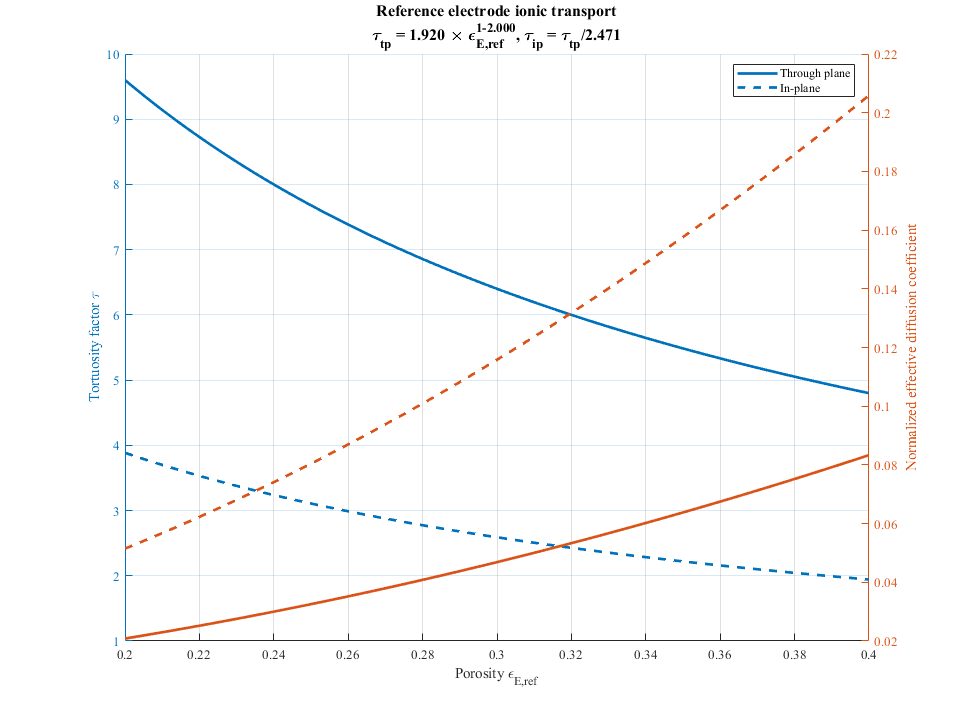

if ~Sintered_case
    figure_plot = false; figure_contour = false;
    Fig_ = figure; % Create figure
    Fig_.Name= 'Reference electrode ionic transport';
    Fig_.Color='white'; % Background colour
    
    % Case 1 parameter is variable
    if n_eps>1 && n_gamma==1 && n_alpha==1
        ax = axes(Fig_);
        hold(ax,'on');
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/2 scrsz(4)/1.5]);
        yyaxis left
        plot(eref,tau_ref_tp(1,:,1,1),eref,tau_ref_ip(1,:,1,1,1),'linewidth',2)
        ylabel('Tortuosity factor \tau');
        yyaxis right
        plot(eref,Dn_ref_tp(1,:,1,1),eref,Dn_ref_ip(1,:,1,1,1),'linewidth',2)
        ylabel('Normalized effective diffusion coefficient');
        xlabel('Porosity \epsilon_{E,ref}');
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = %1.3f \\times \\epsilon_{E,ref}^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],gamma(1),alpha(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times \\epsilon_{E,ref} + %1.3f) \\times  %1.3f \\times (\\epsilon_{E,ref}+\\epsilon_{CBD,ref})^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,b,gamma(1),alpha(1),aniso(1));
        end
        figure_plot=true;
    elseif n_eps==1 && n_gamma>1 && n_alpha==1
        ax = axes(Fig_);
        hold(ax,'on');
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/2 scrsz(4)/1.5]);
        yyaxis left
        tmp1=reshape(tau_ref_tp(1,1,:,1),[],numel(tau_ref_tp(1,1,:,1)));
        tmp2=reshape(tau_ref_ip(1,1,:,1,1),[],numel(tau_ref_ip(1,1,:,1,1)));
        plot(gamma,tmp1,gamma,tmp2,'linewidth',2)
        ylabel('Tortuosity factor \tau');
        yyaxis right
        tmp1=reshape(Dn_ref_tp(1,1,:,1),[],numel(Dn_ref_tp(1,1,:,1)));
        tmp2=reshape(Dn_ref_ip(1,1,:,1,1),[],numel(Dn_ref_ip(1,1,:,1,1)));
        plot(gamma,tmp1,gamma,tmp2,'linewidth',2)
        ylabel('Normalized effective diffusion coefficient');
        xlabel('\gamma');
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = \\gamma \\times %1.3f^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],eref(1),alpha(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times %1.3f + %1.3f) \\times  \\gamma \\times (%1.3f+ %1.3f)^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,eref(1),b,eref(1),ecbdref(1),alpha(1),aniso(1));
        end
        figure_plot=true;
    elseif n_eps==1 && n_gamma==1 && n_alpha>1
        ax = axes(Fig_);
        hold(ax,'on');
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/2 scrsz(4)/1.5]); % Full screen figure
        yyaxis left
        tmp1=reshape(tau_ref_tp(1,1,1,:),[],numel(tau_ref_tp(1,1,1,:)));
        tmp2=reshape(tau_ref_ip(1,1,1,:,1),[],numel(tau_ref_ip(1,1,1,:,1)));
        plot(alpha,tmp1,alpha,tmp2,'linewidth',2)
        ylabel('Tortuosity factor \tau');
        yyaxis right
        tmp1=reshape(Dn_ref_tp(1,1,1,:),[],numel(Dn_ref_tp(1,1,1,:)));
        tmp2=reshape(Dn_ref_ip(1,1,1,:,1),[],numel(Dn_ref_ip(1,1,1,:,1)));
        plot(alpha,tmp1,alpha,tmp2,'linewidth',2)
        ylabel('Normalized effective diffusion coefficient');
        xlabel('\alpha');
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = %1.3f \\times %1.3f^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],gamma(1),eref(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times %1.3f + %1.3f) \\times  %1.3f \\times (%1.3f+ %1.3f)^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,eref(1),b,gamma(1),eref(1),ecbdref(1),aniso(1));
        end
        figure_plot=true;
        
        
        % Case 2 parameters variable
    elseif n_eps>1 && n_gamma>1 && n_alpha==1
        [X_,Y_] = meshgrid(eref,gamma);
        set(Fig_,'position',scrsz); % Full screen figure
        for id_axe=1:1:4 % Iterate over axe
            sub_axes=subplot(2,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title('Through-plane tortuosity factor'); % - Title
                tmp1=zeros(n_gamma,n_eps);
                for k=1:1:n_eps
                    tmp1(:,k) = tau_ref_tp(1,k,:,1);
                end
            elseif id_axe==2
                t_title=title('Through-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = Dn_ref_tp(1,k,:,1);
                end
            elseif id_axe==3
                t_title=title('In-plane tortuosity factor'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = tau_ref_ip(1,k,:,1,1);
                end
            elseif id_axe==4
                t_title=title('In-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = Dn_ref_ip(1,k,:,1,1);
                end
            end
            contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
            colorbar
            xlabel(str_eref);
            ylabel('\gamma');
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = \\gamma \\times \\epsilon_{E,ref}^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],alpha(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times \\epsilon_{E,ref} + %1.3f) \\times  \\gamma \\times (\\epsilon_{E,ref}+\\epsilon_{CBD,ref})^{1-%1.3f}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,b,alpha(1),aniso(1));
        end
        figure_contour = true;
        
    elseif n_eps>1 && n_gamma==1 && n_alpha>1
        [X_,Y_] = meshgrid(eref,alpha);
        set(Fig_,'position',scrsz); % Full screen figure
        for id_axe=1:1:4 % Iterate over axe
            sub_axes=subplot(2,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title('Through-plane tortuosity factor'); % - Title
                tmp1=zeros(n_alpha,n_eps);
                for k=1:1:n_eps
                    tmp1(:,k) = tau_ref_tp(1,k,1,:);
                end
            elseif id_axe==2
                t_title=title('Through-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = Dn_ref_tp(1,k,1,:);
                end
            elseif id_axe==3
                t_title=title('In-plane tortuosity factor'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = tau_ref_ip(1,k,1,:,1);
                end
            elseif id_axe==4
                t_title=title('In-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_eps
                    tmp1(:,k) = Dn_ref_ip(1,k,1,:,1);
                end
            end
            contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
            colorbar
            xlabel(str_eref);
            ylabel('\alpha');
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = %1.3f \\times \\epsilon_{E,ref}^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],gamma(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times \\epsilon_{E,ref} + %1.3f) \\times  %1.3f \\times (\\epsilon_{E,ref}+\\epsilon_{CBD,ref})^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,b,gamma(1),aniso(1));
        end
        figure_contour = true;
        
    elseif n_eps==1 && n_gamma>1 && n_alpha>1
        [X_,Y_] = meshgrid(gamma,alpha);
        set(Fig_,'position',scrsz); % Full screen figure
        for id_axe=1:1:4 % Iterate over axe
            sub_axes=subplot(2,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title('Through-plane tortuosity factor'); % - Title
                tmp1=zeros(n_alpha,n_gamma);
                for k=1:1:n_gamma
                    tmp1(:,k) = tau_ref_tp(1,1,k,:);
                end
            elseif id_axe==2
                t_title=title('Through-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_gamma
                    tmp1(:,k) = Dn_ref_tp(1,1,k,:);
                end
            elseif id_axe==3
                t_title=title('In-plane tortuosity factor'); % - Title
                for k=1:1:n_gamma
                    tmp1(:,k) = tau_ref_ip(1,1,k,:,1);
                end
            elseif id_axe==4
                t_title=title('In-plane normalized diffusion coeffcient'); % - Title
                for k=1:1:n_gamma
                    tmp1(:,k) = Dn_ref_ip(1,1,k,:,1);
                end
            end
            contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
            colorbar
            xlabel('\gamma');
            ylabel('\alpha');
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        if a==0 && b==1
            str_ = sprintf(['\\tau_{tp} = \\gamma \\times %1.3f^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],eref(1),aniso(1));
        else
            str_ = sprintf(['\\tau_{tp} = (%1.3f \\times %1.3f + %1.3f) \\times  \\gamma \\times (%1.3f+%1.3f)^{1-\\alpha}, \\tau_{ip} = \\tau_{tp}/%1.3f'],a,eref(1),b,eref(1),ecbdref(1),aniso(1));
        end
        figure_contour = true;
    end
    
    if figure_plot
        set(ax,'FontName',font_name,'FontSize',font_plot_size); % - Fontname and fontsize
        t_title=title({'Reference electrode ionic transport',str_}); % - Title
        t_title.FontSize=font_plot_size+2;
        legend(ax,'Through plane','In-plane','Location','best'); % Legend
        grid(ax,show_grid); % Major Grid
        set(ax,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
        hold(ax,'off'); % Release current plot
        
    elseif figure_contour
        sgtitle(Fig_,{'Reference electrode ionic transport',str_},'FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
    else
        close(Fig_)
    end
    if figure_plot || figure_contour
        filename= 'Reference_transport_properties'; % Save figures
        fullpath = [save_folder filename];
        if save_png
            saveas(Fig_,fullpath,'png')
        end
        if save_fig
            set(Fig_, 'Visible', 'on');
            savefig(Fig_,fullpath)
        end
    end
end

### Structured electrode transport properties

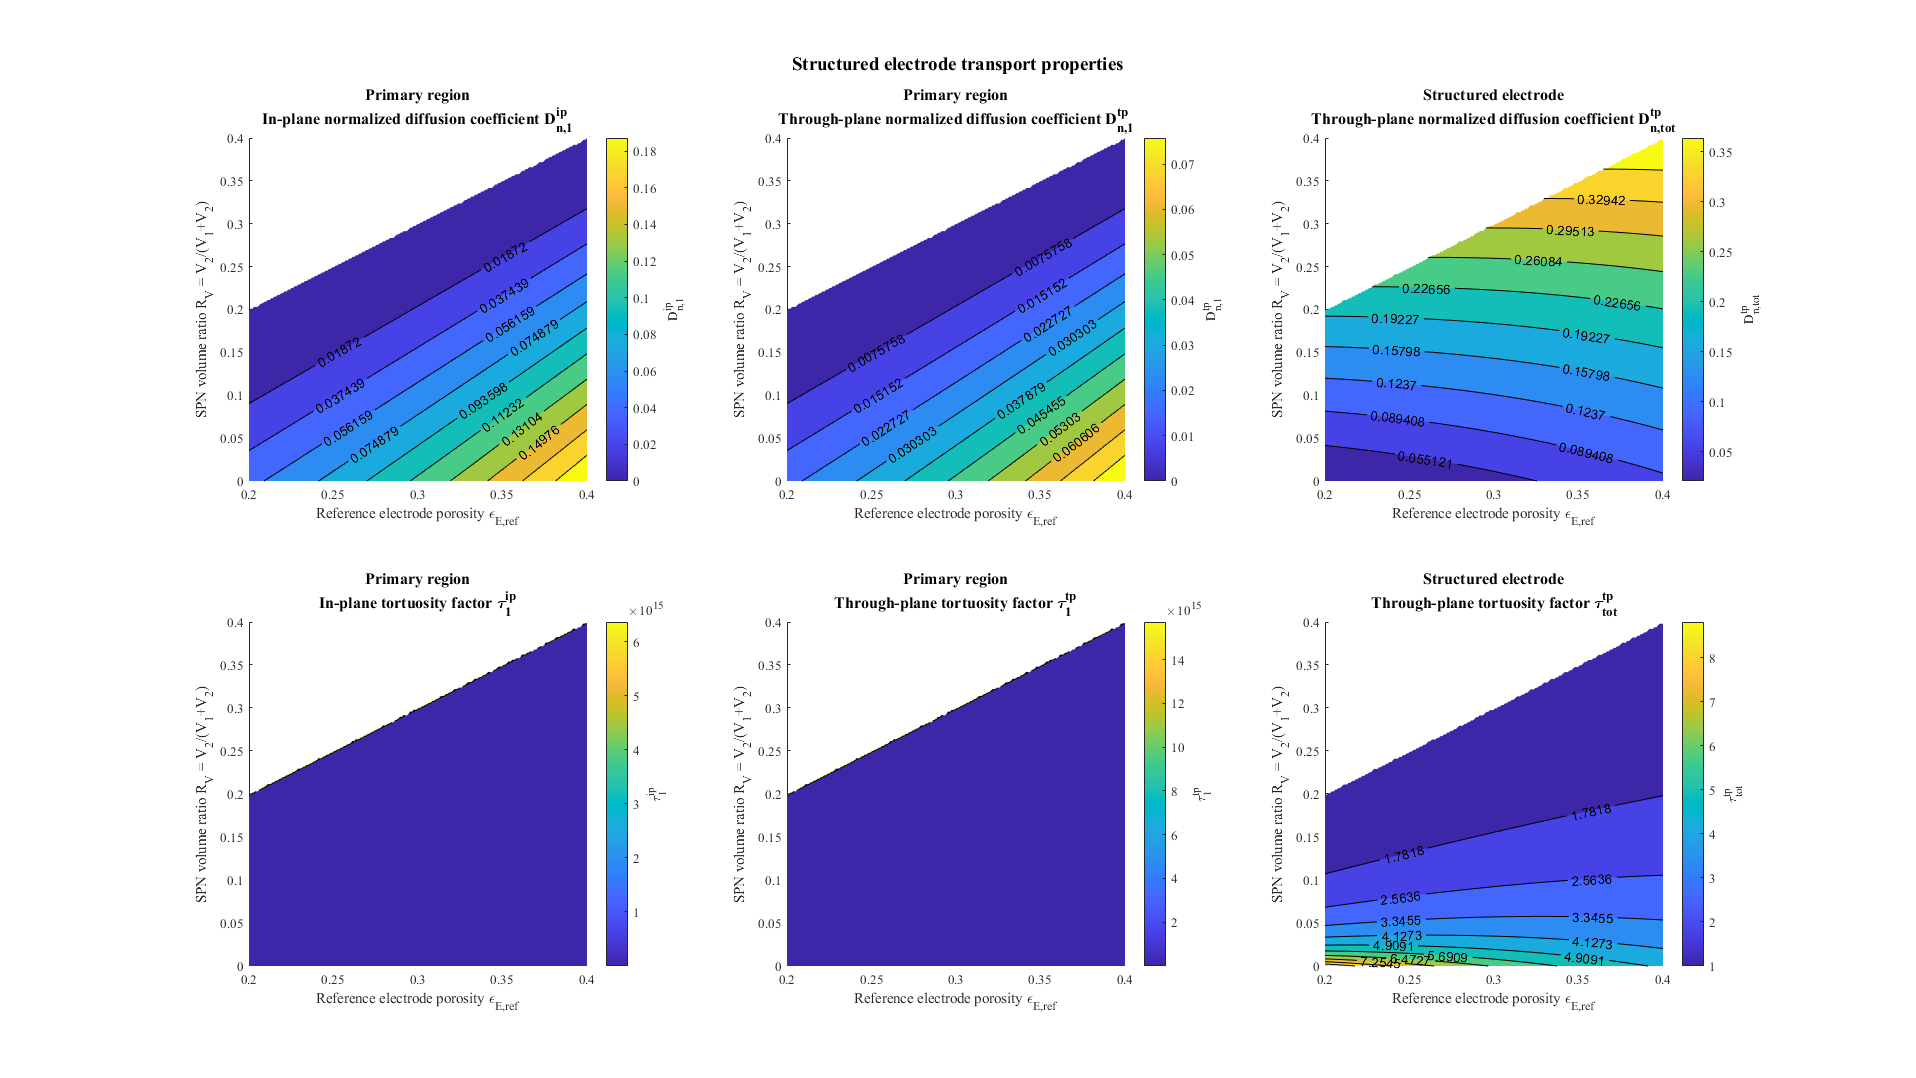

if ~Sintered_case
    if strcmp(bilayer_plot,'PS')
        Dn_tot_tp_plot = Dn_tot_tp_star;
        tau_tot_tp_plot = tau_tot_tp_star;
        D_tot_g_tp_plot = D_tot_g_tp_star;
        gain_product_plot = gain_product_star;
        max_gain_plot = max_gain_star;
        D_ratio_plot = D_ratio_star;
        D_ratio_opt2_plot = D_ratio_opt2_star;
        D_ratio_opt3_plot = D_ratio_opt3_star;
    elseif strcmp(bilayer_plot,'SP')
        Dn_tot_tp_plot = Dn_tot_tp_star2;
        tau_tot_tp_plot = tau_tot_tp_star2;
        D_tot_g_tp_plot = D_tot_g_tp_star2;
        gain_product_plot = gain_product_star2;
        max_gain_plot = max_gain_star2;
        D_ratio_plot = D_ratio_star2;
        D_ratio_opt2_plot = D_ratio_opt2_star2;
        D_ratio_opt3_plot = D_ratio_opt3_star2;
    end
    
    figure_plot = false;
    Fig_ = figure; % Create figure
    Fig_.Name= 'Structured electrode ionic transport';
    Fig_.Color='white'; % Background colour
    % Select data case
    if n_eps==1 && n_alpha==1 && n_gamma==1 % Rv is the only variable: 1D plot
        if n_aniso==1
            set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/2 scrsz(4)/2]);
            for id_axe=1:1:2 % Iterate over axe
                sub_axes=subplot(1,2,id_axe,'Parent',Fig_);
                hold(sub_axes,'on'); % Active subplot
                if id_axe==1
                    plot(x_R,Dn_1_ip(:,1,1,1,1),'linewidth',2)
                    plot(x_R,Dn_1_tp(:,1,1,1),'linewidth',2)
                    plot(x_R,Dn_tot_tp_plot(:,1,1,1),'linewidth',2)
                    ylabel('D_{n}');
                    legend(sub_axes,'Primary region D_{n,1}^{ip}','Primary region D_{n,1}^{tp}','Structured electrode D_{n,tot}^{tp}','Location','best'); % Legend
                elseif id_axe==2
                    plot(x_R,tau_1_ip(:,1,1,1,1),'linewidth',2)
                    plot(x_R,tau_1_tp(:,1,1,1),'linewidth',2)
                    plot(x_R,tau_tot_tp_plot(:,1,1,1),'linewidth',2)
                    ylabel('\tau');
                    legend(sub_axes,'Primary region \tau_{1}^{ip}','Primary region \tau_{1}^{tp}','Structured electrode \tau_{tot}^{tp}','Location','best'); % Legend
                end
                xlabel(R_label)
                grid(sub_axes,show_grid); % Major Grid
                set(sub_axes,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
                set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
                t_title.FontSize=font_plot_size+2;
                hold(sub_axes,'off'); % Release current subplot
            end
        else
            [X_,Y_] = meshgrid(x_R,aniso);
            set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)/1.5 scrsz(4)/1.5]);
            for id_axe=1:1:4 % Iterate over axe
                sub_axes=subplot(2,2,id_axe,'Parent',Fig_);
                hold(sub_axes,'on'); % Active subplot
                if id_axe==1
                    t_title=title('Through-plane normalized diffusion coefficient D_{n}^{tp}'); % - Title
                    plot(x_R,Dn_1_tp(:,1,1,1),'linewidth',2)
                    plot(x_R,Dn_tot_tp_plot(:,1,1,1),'linewidth',2)
                    ylabel('D_{n}^{tp}');
                    legend(sub_axes,'Primary region D_{n,1}^{tp}','Structured electrode D_{n,tot}^{tp}','Location','best'); % Legend
                    grid(sub_axes,show_grid); % Major Grid
                    set(sub_axes,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
                elseif id_axe==2
                    t_title=title('Through-plane tortuosity factor \tau^{tp}'); % - Title
                    plot(x_R,tau_1_tp(:,1,1,1),'linewidth',2)
                    plot(x_R,tau_tot_tp_plot(:,1,1,1),'linewidth',2)
                    ylabel('\tau^{tp}');
                    legend(sub_axes,'Primary region \tau_{1}^{tp}','Structured electrode \tau_{tot}^{tp}','Location','best'); % Legend
                    grid(sub_axes,show_grid); % Major Grid
                    set(sub_axes,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
                elseif id_axe==3
                    t_title=title('In-plane normalized diffusion coefficient \tau^{ip}'); % - Title
                    tmp1=zeros(n_R,n_aniso);
                    for k=1:1:n_aniso
                        tmp1(:,k) = Dn_1_ip(:,1,1,1,k);
                    end
                    contourf(X_,Y_,tmp1',n_isolines,'ShowText',show_isovalue)
                    ylabel('\tau^{tp/ip}')
                elseif id_axe==4
                    t_title=title('In-plane normalized tortuosity factor \tau^{ip}'); % - Title
                    tmp1=zeros(n_R,n_aniso);
                    for k=1:1:n_aniso
                        tmp1(:,k) = tau_1_ip(:,1,1,1,k);
                    end
                    contourf(X_,Y_,tmp1',n_isolines,'ShowText',show_isovalue)
                    ylabel('\tau^{tp/ip}')
                end
                t_title.FontSize=font_plot_size+2;
                xlabel(R_label)
                set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
                t_title.FontSize=font_plot_size+2;
                hold(sub_axes,'off'); % Release current subplot
            end
        end
        figure_plot=true;
    elseif n_eps>1 && n_alpha==1 && n_gamma==1 || n_eps==1 && n_alpha>1 && n_gamma==1 || n_eps==1 && n_alpha==1 && n_gamma>1
        if n_eps>1 && n_alpha==1 && n_gamma==1
            [X_,Y_] = meshgrid(eref,x_R);
            str_x = str_eref;
            tmp1=zeros(n_R,n_eps); n_ = n_eps;
        elseif n_eps==1 && n_alpha>1 && n_gamma==1
            [X_,Y_] = meshgrid(alpha,x_R);
            str_x = str_alpha;
            tmp1=zeros(n_R,n_alpha); n_ = n_alpha;
        elseif n_eps==1 && n_alpha==1 && n_gamma>1
            [X_,Y_] = meshgrid(gamma,x_R);
            str_x = str_gamma;
            tmp1=zeros(n_R,n_gamma); n_ = n_gamma;
        end
        set(Fig_,'position',scrsz); % Full screen
        for id_axe=1:1:6 % Iterate over axe
            sub_axes=subplot(2,3,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title({'Primary region','In-plane normalized diffusion coefficient D_{n,1}^{ip}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = Dn_1_ip(:,k,1,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = Dn_1_ip(:,1,1,k,1);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = Dn_1_ip(:,1,k,1,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, 'D_{n,1}^{ip}');
            elseif id_axe==2
                t_title=title({'Primary region','Through-plane normalized diffusion coefficient D_{n,1}^{tp}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = Dn_1_tp(:,k,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = Dn_1_tp(:,1,1,k);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = Dn_1_tp(:,1,k,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, 'D_{n,1}^{tp}');
            elseif id_axe==3
                t_title=title({'Structured electrode','Through-plane normalized diffusion coefficient D_{n,tot}^{tp}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = Dn_tot_tp_plot(:,k,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = Dn_tot_tp_plot(:,1,1,k);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = Dn_tot_tp_plot(:,1,k,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, 'D_{n,tot}^{tp}');
            elseif id_axe==4
                t_title=title({'Primary region','In-plane tortuosity factor \tau_{1}^{ip}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = tau_1_ip(:,k,1,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = tau_1_ip(:,1,1,k,1);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = tau_1_ip(:,1,k,1,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, '\tau_{1}^{ip}');
            elseif id_axe==5
                t_title=title({'Primary region','Through-plane tortuosity factor \tau_{1}^{tp}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = tau_1_tp(:,k,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = tau_1_tp(:,1,1,k);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = tau_1_tp(:,1,k,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, '\tau_{1}^{tp}');
            elseif id_axe==6
                t_title=title({'Structured electrode','Through-plane tortuosity factor \tau_{tot}^{tp}'}); % - Title
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = tau_tot_tp_plot(:,k,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = tau_tot_tp_plot(:,1,1,k);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = tau_tot_tp_plot(:,1,k,1);
                    end
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                h=colorbar(sub_axes);
                ylabel(h, '\tau_{tot}^{tp}');
            end
            set(h,'FontName',font_name,'FontSize',font_plot_size);
            t_title.FontSize=font_plot_size+2;
            xlabel(str_x)
            ylabel(R_label)
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        figure_plot=true;
    end
    if figure_plot
        sgtitle(Fig_,'Structured electrode transport properties','FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        if RL==1
            filename= ['Structured_electrode_transport_properties_' char(Channel_geometry) '_' str_sav]; % Save figure
        else
            filename= ['Structured_electrode_transport_properties_RL' num2str(100*RL,'%1.0f') '_' char(Channel_geometry) '_' str_sav]; % Save figure
        end
        fullpath = [save_folder filename];
        if save_png
            saveas(Fig_,fullpath,'png')
        end
        if save_fig
            set(Fig_, 'Visible', 'on');
            savefig(Fig_,fullpath)
        end
    end
end

### **Optimization** objective 1: maximize diffusion gain

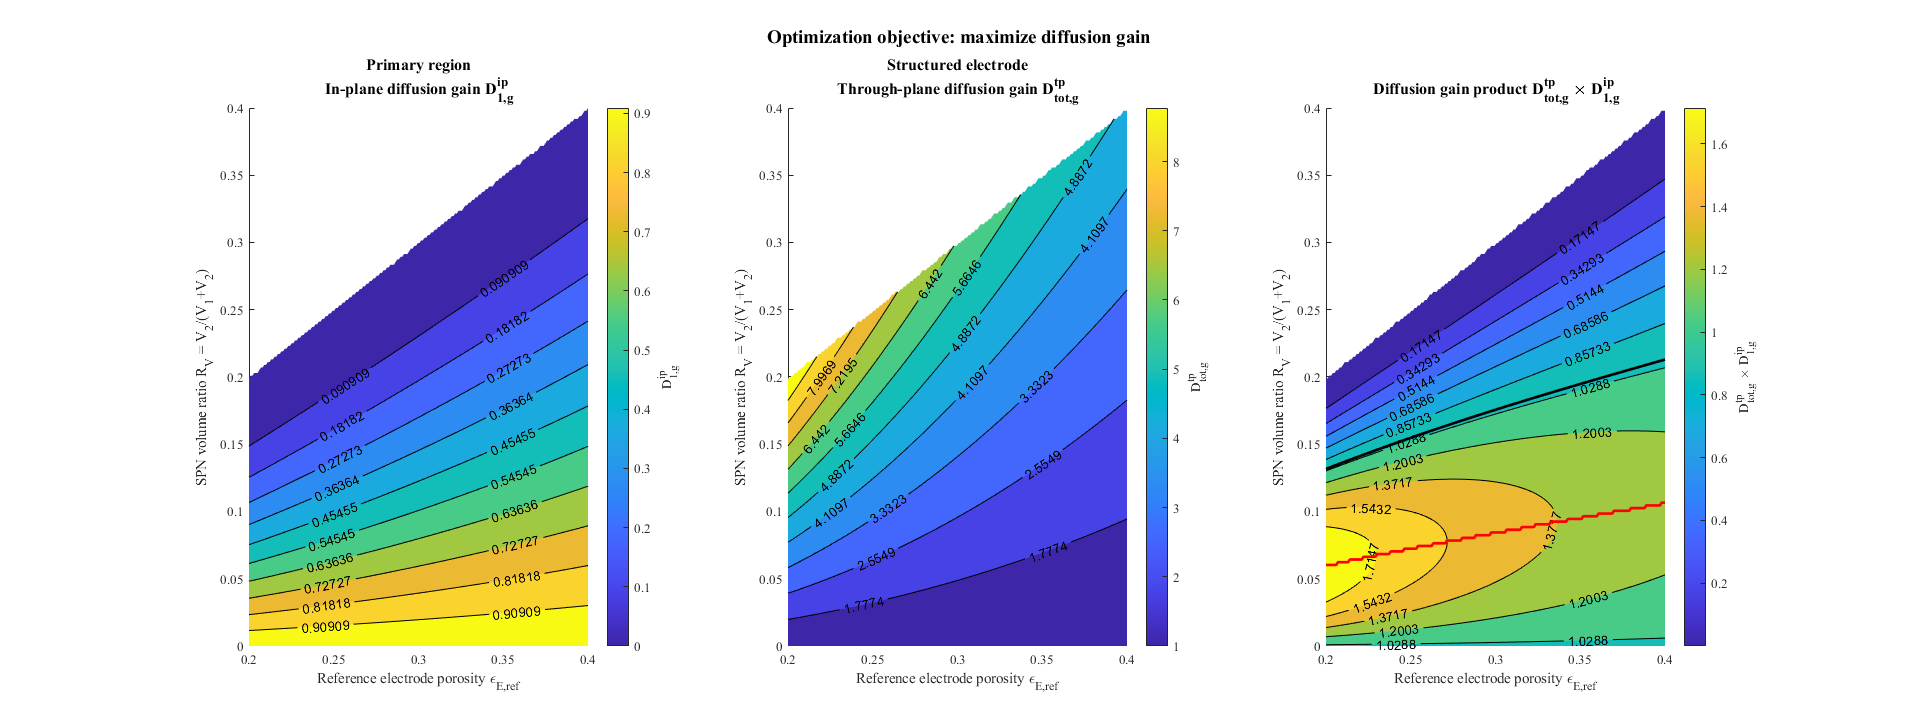

if ~Sintered_case
    figure_plot = false;
    Fig_ = figure; % Create figure
    Fig_.Name= 'Diffusion gain';
    Fig_.Color='white'; % Background colour
    % Select data case
    if n_eps==1 && n_alpha==1 && n_gamma==1 % Rv is the only variable: 1D plot
        figure_plot=true;
        ax = axes(Fig_);
        hold(ax,'on');
        t_title=title({'Diffusion gain (electrode through plane)','and loss (primary region in-plane)'}); % - Title
        tmp1=reshape(D_1_g_ip(:,1,1,1),[],numel(D_1_g_ip(:,1,1,1)));
        if strcmp(In_planediffusion_plot,'Gain')
            plot(x_R,tmp1,'linewidth',2);
            str_legend_1 = 'Primary region diffusion gain D_{1,g}^{ip}';
        elseif strcmp(In_planediffusion_plot,'Loss')
            plot(x_R,1./tmp1,'linewidth',2)
            str_legend_1 = 'Primary region diffusion loss 1/D_{1,g}^{ip}';
        end
        tmp1=reshape(D_tot_g_tp_plot(:,1,1,1),[],numel(D_tot_g_tp_plot(:,1,1,1)));
        plot(x_R,tmp1,'linewidth',2)
        tmp1=reshape(gain_product_plot(:,1,1,1),[],numel(gain_product_plot(:,1,1,1)));
        plot(x_R,tmp1,'linewidth',2)
        x_max = interp1([1:1:n_R],x_R,max_gain_plot(1,1,1,2));
        y_max = max_gain_plot(1,1,1,1);
        plot([x_max x_max],[0 y_max],'linewidth',2,'LineStyle',"--","Color",'k');
        xl = xlim;
        plot([0 xl(2)],[1 1],'linewidth',2,'LineStyle',"--","Color",[0.5 0.5 0.5]);
        plot([0 x_max],[y_max y_max],'linewidth',2,'LineStyle',"--","Color",'k');
        str_legend = {str_legend_1,'Structured electrode through-plane diffusion gain D_{tot,g}^{tp}','Diffusion gain product D_{tot,g}^{tp} \times D_{1,g}^{ip}','Optimal ratio','Unit'};
        legend(ax,str_legend,'Location','best'); % Legend
        ylabel('Diffusion gain and loss');
        xlabel(R_label)
        set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
        t_title.FontSize=font_plot_size+2;
        grid(ax,show_grid); % Major Grid
        set(ax,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
    elseif n_eps>1 && n_alpha==1 && n_gamma==1 || n_eps==1 && n_alpha>1 && n_gamma==1 || n_eps==1 && n_alpha==1 && n_gamma>1
        if n_eps>1 && n_alpha==1 && n_gamma==1
            x_var = eref;
            str_x = str_eref;
            n_ = n_eps;
        elseif n_eps==1 && n_alpha>1 && n_gamma==1
            x_var = alpha;
            str_x = str_alpha;
            n_ = n_alpha;
        elseif n_eps==1 && n_alpha==1 && n_gamma>1
            x_var = gamma;
            str_x = str_gamma;
            n_ = n_gamma;
        end
        [X_,Y_] = meshgrid(x_var,x_R);
        tmp1=zeros(n_R,n_);
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3) scrsz(4)/1.5]);
        for id_axe=1:1:3 % Iterate over axe
            sub_axes=subplot(1,3,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = D_1_g_ip(:,k,1,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = D_1_g_ip(:,1,1,k,1);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = D_1_g_ip(:,1,k,1,1);
                    end
                end
                if strcmp(In_planediffusion_plot,'Gain')
                    t_title=title({'Primary region','In-plane diffusion gain D_{1,g}^{ip}'}); % - Title
                    str_h = 'D_{1,g}^{ip}';
                elseif strcmp(In_planediffusion_plot,'Loss')
                    t_title=title({'Primary region','In-plane diffusion loss 1/D_{1,g}^{ip}'}); % - Title
                    str_h = '1/D_{1,g}^{ip}';
                    tmp1=1./tmp1;
                end
                if strcmp(Comparison_choice,"Porosity_constant")
                    tmp1=round(tmp1,3); % D_1_g_ip = 1 + machine error, resulting in a contour map numerically hard to plot.
                end
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
            elseif id_axe==2
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = D_tot_g_tp_plot(:,k,1,1,1);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = D_tot_g_tp_plot(:,1,1,k,1);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1  tmp1(:,k) = D_tot_g_tp_plot(:,1,k,1,1);
                    end
                end
                t_title=title({'Structured electrode','Through-plane diffusion gain D_{tot,g}^{tp}'}); % - Title
                str_h = 'D_{tot,g}^{tp}';
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
            elseif id_axe==3
                for k=1:1:n_
                    if n_eps>1 && n_alpha==1 && n_gamma==1; tmp1(:,k) = gain_product_plot(:,k,1,1,1); idx_max = max_gain_plot(:,1,1,2); idx_unit = max_gain_plot(:,1,1,3);
                    elseif n_eps==1 && n_alpha>1 && n_gamma==1; tmp1(:,k) = gain_product_plot(:,1,1,k,1); idx_max = max_gain_plot(1,1,:,2); idx_unit = max_gain_plot(1,1,:,3);
                    elseif n_eps==1 && n_alpha==1 && n_gamma>1; tmp1(:,k) = gain_product_plot(:,1,k,1,1); idx_max = max_gain_plot(1,:,1,2); idx_unit = max_gain_plot(1,:,1,3);
                    end
                end
                t_title=title('Diffusion gain product D_{tot,g}^{tp} \times D_{1,g}^{ip}'); % - Title
                str_h = 'D_{tot,g}^{tp} \times D_{1,g}^{ip}';
                contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
                x_unit = interp1([1:1:n_R],x_R,idx_unit);
                id_nan=find(isnan(x_unit));
                x_unit(id_nan)=[]; x_var_tmp=x_var; x_var_tmp(id_nan)=[];
                if ~isempty(x_unit)
                    plot(x_var_tmp,reshape(x_unit,[],length(x_unit)),'linewidth',2,"Color",'k')
                end                   
                y_max = x_R(idx_max);
                plot(x_var,y_max,'linewidth',2,"Color",'r')
            end
            h=colorbar(sub_axes);
            ylabel(h, str_h);
            set(h,'FontName',font_name,'FontSize',font_plot_size);
            t_title.FontSize=font_plot_size+2;
            xlabel(str_x)
            ylabel(R_label)
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        sgtitle(Fig_,'Optimization objective: maximize diffusion gain','FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        figure_plot=true;
    
    elseif n_eps>1 && n_alpha>1 && n_gamma==1 || n_eps>1 && n_alpha==1 && n_gamma>1 || n_eps==1 && n_alpha>1 && n_gamma>1
        if n_eps>1 && n_alpha>1 && n_gamma==1
            x_var = eref; y_var = alpha;
            str_x = str_eref; str_y = str_alpha;
            n_x = n_eps; n_y = n_alpha;
        elseif n_eps>1 && n_alpha==1 && n_gamma>1
            x_var = eref; y_var = gamma;
            str_x = str_eref; str_y = str_gamma;
            n_x = n_eps; n_y = n_gamma;
        elseif n_eps==1 && n_alpha>1 && n_gamma>1
            x_var = alpha; y_var = gamma;
            str_x = str_alpha; str_y = str_gamma;
            n_ = n_alpha; n_y = n_gamma;
        end
        [X_,Y_] = meshgrid(x_var,y_var);
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)*3/4 scrsz(4)/2]);
        tmp_opt1 = zeros(n_x,n_y);
        tmp_max = zeros(n_x,n_y);
        for kx=1:1:n_x
            for ky=1:1:n_y
                if     n_eps>1  && n_alpha>1  && n_gamma==1; tmp_opt1(kx,ky)=max_gain_plot(kx,1,ky,2); tmp_max(kx,ky)=max_gain_plot(kx,1,ky,1);
                elseif n_eps>1  && n_alpha==1 && n_gamma>1 ; tmp_opt1(kx,ky)=max_gain_plot(kx,ky,1,2); tmp_max(kx,ky)=max_gain_plot(kx,ky,1,1);
                elseif n_eps==1 && n_alpha>1  && n_gamma>1 ; tmp_opt1(kx,ky)=max_gain_plot(1,ky,kx,2); tmp_max(kx,ky)=max_gain_plot(1,ky,kx,1);
                end
            end
        end
        % Interpolate
        opt1 = zeros(n_x,n_y);
        for kx=1:1:n_x
            opt1(kx,:) = interp1([1:1:n_R],x_R,tmp_opt1(kx,:));
        end
        for id_axe=1:1:2 % Iterate over axe
            sub_axes=subplot(1,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title(' Maximum Diffusion gain product D_{tot,g}^{tp} \times D_{1,g}^{ip}'); % - Title
                str_h = 'D_{tot,g}^{tp} \times D_{1,g}^{ip}';
                contourf(X_,Y_,tmp_max',n_isolines,'ShowText',show_isovalue)
            elseif id_axe==2
                t_title=title(['Optimal ' R_label]); % - Title
                str_h = R_label;
                contourf(X_,Y_,opt1',n_isolines,'ShowText',show_isovalue)
            end
            h=colorbar(sub_axes);
            ylabel(h, R_label);
            set(h,'FontName',font_name,'FontSize',font_plot_size);
            t_title.FontSize=font_plot_size+2;
            xlabel(str_x)
            ylabel(str_y)
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        sgtitle(Fig_,'Optimization objective: maximize diffusion gain','FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        figure_plot=true;
    end
        
    if figure_plot
        if RL==1
            filename= ['Diffusion_gain_' char(Channel_geometry) '_' str_sav]; % Save figure
        else
            filename= ['Diffusion_gain_RL' num2str(100*RL,'%1.0f') '_' char(Channel_geometry) '_' str_sav]; % Save figure
        end
        fullpath = [save_folder filename];
        if save_png
            saveas(Fig_,fullpath,'png')
        end
        if save_fig
            set(Fig_, 'Visible', 'on');
            savefig(Fig_,fullpath)
        end
    end
end

### **Optimization** objective 2, enforce isotropic diffusion coefficient and 3: enforce isotropic characteristic diffusion time

Between the structured electrode through-plane and the primary region in-plane.

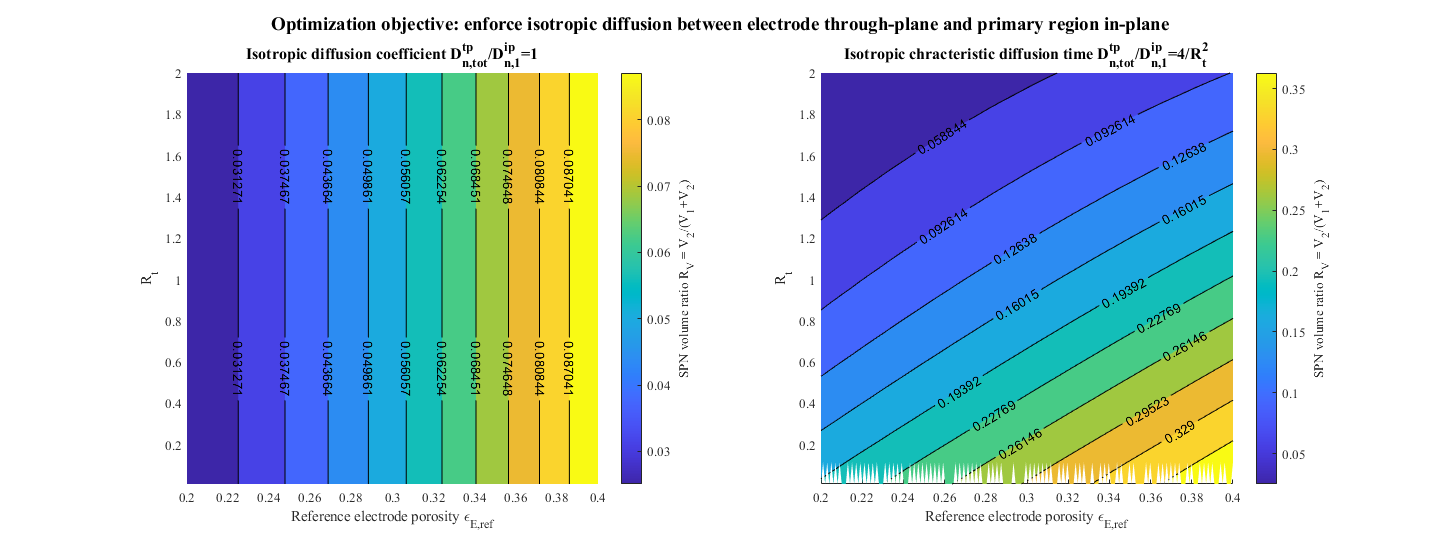

if ~Sintered_case 
    figure_plot = false;
    Fig_ = figure; % Create figure
    Fig_.Name= 'Diffusion gain';
    Fig_.Color='white'; % Background colour
    
    % Select data case
    if n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT==1 % Rv is the only variable: 1D plot
        ax = axes(Fig_);
        hold(ax,'on');
        t_title=title({'Structured electrode, isotropy between','electrode through-plane and primary region in-plane'}); % - Title
        tmp1=reshape(D_ratio_plot(:,1,1,1,1),[],numel(D_ratio_plot(:,1,1,1,1)));
        plot(x_R,tmp1,'linewidth',2);
        str_legend = {'D_{n,tot}^{tp}/D_{n,1}^{ip}'};
        y_obj2 = 1;
        x_obj2 = interp1([1:1:n_R],x_R,D_ratio_opt2_plot(1,1,1,1))
        y_obj3 = 4/(Rt(1)^2);
        x_obj3 = interp1([1:1:n_R],x_R,D_ratio_opt3_plot(1,1,1,1))
        if ~isnan(x_obj2)
            plot([x_obj2 x_obj2],[0 y_obj2],'linewidth',2,'LineStyle',"--","Color",'k');
            plot([0 x_obj2],[y_obj2 y_obj2],'linewidth',2,'LineStyle',"--","Color",'k');
            str_legend(length(str_legend)+1) = {'D_{n,tot}^{tp}/D_{n,1}^{ip} = 1'};
        end
        if ~isnan(x_obj3)
            plot([x_obj3 x_obj3],[0 y_obj3],'linewidth',2,'LineStyle',"--","Color",'r');
            plot([0 x_obj3],[y_obj3 y_obj3],'linewidth',2,'LineStyle',"--","Color",'r');
            str_legend(length(str_legend)+1) = {'D_{n,tot}^{tp}/D_{n,1}^{ip} = 4/R_{t}^{2}'};
        end
        legend(ax,str_legend,'Location','best'); % Legend
        ylabel('D_{n,tot}^{tp}/D_{n,1}^{ip}');
        grid(ax,show_grid); % Major Grid
        set(ax,'XMinorGrid',show_minorgrid,'YMinorGrid',show_minorgrid); % Minor Grid
        ylabel(R_label)
        set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
        t_title.FontSize=font_plot_size+2;
        figure_plot=true;
    elseif n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT==1 || n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT==1 ||...
            n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT==1 || n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT==1 ||...
            n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1 % 1 Variable + Rv: 2D map showing diffusion ratio
        ax = axes(Fig_);
        hold(ax,'on');
        t_title=title({'Structured electrode, isotropy between','electrode through-plane and primary region in-plane'}); % - Title
        if n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT==1
            x_var = eref;
            str_x = str_eref;
            n_ = n_eps;
        elseif n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT==1
            x_var = alpha;
            str_x = str_alpha;
            n_ = n_alpha;
        elseif n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT==1
            x_var = gamma;
            str_x = str_gamma;
            n_ = n_gamma;
        elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT==1
            x_var = aniso;
            str_x = str_aniso;
            n_ = n_aniso;
        elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1
            x_var = Rt;
            str_x = str_Rt;
            n_ = n_RT;
        end
        [X_,Y_] = meshgrid(x_var,x_R);
        tmp1=zeros(n_R,n_);
        tmp_opt2 = zeros(n_,1);
        tmp_opt3 = zeros(n_,1);
        for k=1:1:n_
            if     n_eps>1  && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT==1; tmp1(:,k) = D_ratio_plot(:,k,1,1,1); tmp_opt2(k)=D_ratio_opt2_plot(k,1,1,1); tmp_opt3(k)=D_ratio_opt3_plot(k,1,1,1,1);
            elseif n_eps==1 && n_alpha>1  && n_gamma==1 && n_aniso==1 && n_RT==1; tmp1(:,k) = D_ratio_plot(:,1,1,k,1); tmp_opt2(k)=D_ratio_opt2_plot(1,1,k,1); tmp_opt3(k)=D_ratio_opt3_plot(1,1,k,1,1);
            elseif n_eps==1 && n_alpha==1 && n_gamma>1  && n_aniso==1 && n_RT==1; tmp1(:,k) = D_ratio_plot(:,1,k,1,1); tmp_opt2(k)=D_ratio_opt2_plot(1,k,1,1); tmp_opt3(k)=D_ratio_opt3_plot(1,k,1,1,1);
            elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso>1  && n_RT==1; tmp1(:,k) = D_ratio_plot(:,1,1,1,k); tmp_opt2(k)=D_ratio_opt2_plot(1,1,1,k); tmp_opt3(k)=D_ratio_opt3_plot(1,1,1,k,1);
            elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1;  tmp1(:,k) = D_ratio_plot(:,1,1,1,1); tmp_opt2(k)=D_ratio_opt2_plot(1,1,1,1); tmp_opt3(k)=D_ratio_opt3_plot(1,1,1,1,k);
            end
        end
        contourf(X_,Y_,tmp1,n_isolines,'ShowText',show_isovalue)
        h=colorbar(ax);
        ylabel(h, 'D_{n,tot}^{tp}/D_{n,1}^{ip}');
        set(h,'FontName',font_name,'FontSize',font_plot_size);
        x_obj2 = interp1([1:1:n_R],x_R,tmp_opt2);
        plot(x_var,x_obj2,'linewidth',2,'Color','k');
        x_obj3 = interp1([1:1:n_R],x_R,tmp_opt3);
        plot(x_var,x_obj3,'linewidth',2,'Color','r');
        xlabel(str_x)
        ylabel(R_label)
        set(ax,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
        t_title.FontSize=font_plot_size+2;
        figure_plot=true;
    elseif n_eps>1 && (n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT==1 || n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT==1 || n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT==1 || n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1) ||...
            n_alpha>1 && (n_eps==1 && n_gamma>1 && n_aniso==1 && n_RT==1 || n_eps==1 && n_gamma==1 && n_aniso>1 && n_RT==1 || n_eps==1 && n_gamma==1 && n_aniso==1 && n_RT>1) ||...
            n_gamma>1 && (n_eps==1 && n_alpha==1 && n_aniso>1 && n_RT==1 || n_eps==1 && n_alpha==1 && n_aniso==1 && n_RT>1 ) ||...
            n_aniso>1 && n_eps==1 && n_alpha==1 && n_gamma==1 && n_RT>1 % 2 Variables + Rv: 2D map showing optimal diffusion ratio
        
        if n_eps>1 && n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT==1
            x_var = eref; y_var = alpha;
            str_x = str_eref; str_y = str_alpha;
            n_x = n_eps; n_y = n_alpha;
        elseif n_eps>1 && n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT==1
            x_var = eref; y_var = gamma;
            str_x = str_eref; str_y = str_gamma;
            n_x = n_eps; n_y = n_gamma;
        elseif n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT==1
            x_var = eref; y_var = aniso;
            str_x = str_eref; str_y = str_aniso;
            n_x = n_eps; n_y = n_aniso;
        elseif n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1
            x_var = eref; y_var = Rt;
            str_x = str_eref; str_y = str_Rt;
            n_x = n_eps; n_y = n_RT;
            
        elseif n_eps==1 && n_alpha>1 && n_gamma>1 && n_aniso==1 && n_RT==1
            x_var = alpha; y_var = gamma;
            str_x = str_alpha; str_y = str_gamma;
            n_x = n_alpha; n_y = n_gamma;
        elseif n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso>1 && n_RT==1
            x_var = alpha; y_var = aniso;
            str_x = str_alpha; str_y = str_aniso;
            n_x = n_alpha; n_y = n_aniso;
        elseif n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT>1
            x_var = alpha; y_var = Rt;
            str_x = str_alpha; str_y = str_Rt;
            n_x = n_alpha; n_y = n_RT;
            
        elseif n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso>1 && n_RT==1
            x_var = gamma; y_var = aniso;
            str_x = str_gamma; str_y = str_aniso;
            n_x = n_gamma; n_y = n_aniso;
        elseif n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT>1
            x_var = gamma; y_var = Rt;
            str_x = str_gamma; str_y = str_Rt;
            n_x = n_gamma; n_y = n_RT;
            
        elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT>1
            x_var = aniso; y_var = Rt;
            str_x = str_aniso; str_y = str_Rt;
            n_x = n_aniso; n_y = n_RT;
        end
        
        [X_,Y_] = meshgrid(x_var,y_var);
        tmp_opt2 = zeros(n_x,n_y);
        tmp_opt3 = zeros(n_x,n_y);
        
        % Fill
        for kx=1:1:n_x
            for ky=1:1:n_y
                if     n_eps>1 && n_alpha>1  && n_gamma==1 && n_aniso==1 && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(kx,1,ky,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(kx,1,ky,1,1);
                elseif n_eps>1 && n_alpha==1 && n_gamma>1  && n_aniso==1 && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(kx,ky,1,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(kx,ky,1,1,1);
                elseif n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso>1  && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(kx,1,1,ky); tmp_opt3(kx,ky)=D_ratio_opt3_plot(kx,1,1,ky,1);
                elseif n_eps>1 && n_alpha==1 && n_gamma==1 && n_aniso==1 && n_RT>1 ; tmp_opt2(kx,ky)=D_ratio_opt2_plot(kx,1,1,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(kx,1,1,1,ky);
                    
                elseif n_eps==1 && n_alpha>1 && n_gamma>1  && n_aniso==1 && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,ky,kx,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,ky,kx,1,1);
                elseif n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso>1  && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,1,kx,ky); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,1,kx,ky,1);
                elseif n_eps==1 && n_alpha>1 && n_gamma==1 && n_aniso==1 && n_RT>1 ; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,1,kx,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,1,kx,1,ky);
                    
                elseif n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso>1  && n_RT==1; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,kx,1,ky); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,kx,1,ky,1);
                elseif n_eps==1 && n_alpha==1 && n_gamma>1 && n_aniso==1 && n_RT>1 ; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,kx,1,1); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,kx,1,1,ky);
                    
                elseif n_eps==1 && n_alpha==1 && n_gamma==1 && n_aniso>1 && n_RT>1 ; tmp_opt2(kx,ky)=D_ratio_opt2_plot(1,1,1,kx); tmp_opt3(kx,ky)=D_ratio_opt3_plot(1,1,1,kx,ky);
                end
            end
        end
        
        % Interpolate
        opt2 = zeros(n_x,n_y);
        opt3 = zeros(n_x,n_y);
        for kx=1:1:n_x
            opt2(kx,:) = interp1([1:1:n_R],x_R,tmp_opt2(kx,:));
            opt3(kx,:) = interp1([1:1:n_R],x_R,tmp_opt3(kx,:));
        end
        
        set(Fig_,'position',[scrsz(1) scrsz(2) scrsz(3)*3/4 scrsz(4)/2]);
        for id_axe=1:1:2 % Iterate over axe
            sub_axes=subplot(1,2,id_axe,'Parent',Fig_);
            hold(sub_axes,'on'); % Active subplot
            if id_axe==1
                t_title=title('Isotropic diffusion coefficient D_{n,tot}^{tp}/D_{n,1}^{ip}=1'); % - Title
                contourf(X_,Y_,opt2',n_isolines,'ShowText',show_isovalue)
            elseif id_axe==2
                t_title=title('Isotropic chracteristic diffusion time D_{n,tot}^{tp}/D_{n,1}^{ip}=4/R_{t}^{2}'); % - Title
                contourf(X_,Y_,opt3',n_isolines,'ShowText',show_isovalue)
            end
            h=colorbar(sub_axes);
            ylabel(h, R_label);
            set(h,'FontName',font_name,'FontSize',font_plot_size);
            t_title.FontSize=font_plot_size+2;
            xlabel(str_x)
            ylabel(str_y)
            set(sub_axes,'FontName',font_name,'FontSize',font_plot_size); % Fontname and fontsize
            t_title.FontSize=font_plot_size+2;
            hold(sub_axes,'off'); % Release current subplot
        end
        sgtitle(Fig_,'Optimization objective: enforce isotropic diffusion between electrode through-plane and primary region in-plane','FontWeight','bold','FontSize',font_plot_size+4,'FontName',font_name);
        figure_plot=true;
    end
    if figure_plot
        if RL==1
            filename= ['Diffusion_ratio_' char(Channel_geometry) '_' str_sav]; % Save figure
        else
            filename= ['Diffusion_ratio_RL' num2str(100*RL,'%1.0f') '_' char(Channel_geometry) '_' str_sav]; % Save figure
        end
        fullpath = [save_folder filename];
        if save_png
            saveas(Fig_,fullpath,'png')
        end
        if save_fig
            set(Fig_, 'Visible', 'on');
            savefig(Fig_,fullpath)
        end
    end
    
end

function [x,x_n]=allvalues(x_min,x_max,x_n)
if x_min~=x_max
    x = linspace( min([x_min x_max]), max([x_min x_max]), x_n);
else
    x = x_min;
    x_n = 1;
end
end

function [Rw, A1, A2] = Deduce_Rw_from_Rv(Rv,channel_geometry)
A1 = ones(1,length(Rv));
A2 = -Rv.*A1./(Rv-1);
n=1e3; % Number of primary region
if strcmp(channel_geometry,"Rectangular")
    w1 = A1./n;
    w2 = A2./(n-1);
elseif strcmp(channel_geometry,"Cylindrical")
    %w2 = 2 .* (A2/(pi*n)).^(0.5);
    %a=n; b=2.*n.*w2; c=w2.^2.*n-A2-A1; d = (b.^2 - 4.*a.*c).^(0.5); 
    
    w2 = 2 .* (A2/pi).^(0.5);
    a=1; b=2.*w2; c=(w2.^2)*(1-pi/4)-A1; d = (b.^2 - 4.*a.*c).^(0.5);    
    
    x1 = (-b + d)./(2*a);
    x2 = (-b - d)./(2*a);
    w1 = max([x1;x2],[],1);
end
Rw = w2./w1;
end

function [Rv, A1, A2] = Deduce_Rv_from_Rw(Rw,channel_geometry)
w1 = ones(1,length(Rw));
w2 = Rw.*w1;
n=1e3; % Number of primary region
if strcmp(channel_geometry,"Rectangular")
    A1 = w1.*n;
    A2 = w2.*(n-1);
elseif strcmp(channel_geometry,"Cylindrical")
    A2 = pi.*((w2./2).^2).*n;
    A1 = (w1+w2).^2 .*n -A2;
end
Rv = A2./(A1+A2);
end

function tau = tortuosity_factor(a,b,alpha,gamma,e_pore,e_CBD)
tau=(a*e_pore+b).*(gamma.*(e_pore+e_CBD).^(1-alpha));
end